# FPGA-based Three-Phase PMSM Drive HIL

## Desktop simulation

In desktop simulation, we build, iterate and validate our golden reference model. This is the model with the highest accuracy that we will use to validate any simplification either at model level or solver settings we may apply to make the model compatible with real-time simulation.

Please notice that very often the transition from desktop to real-time simulation involves some trade-offs and design choices that although may cause the loss of some numerical precision in the results, especially, if we look into a long decimal figure or in a tiny fraction of time; those trade-offs will allow us to meet the real-time timing requirements and provide the accuracy good enough so that the plant model can be used to verify and validate the rest of our system.

For the PMSM drive application, we will start with a model made up of a two-level three-phase inverter and a permanent magnet synchronous motor (PMSM), which has been implemented in Simulink using two off-the-shelf blocks from the Simscape Electrical library.

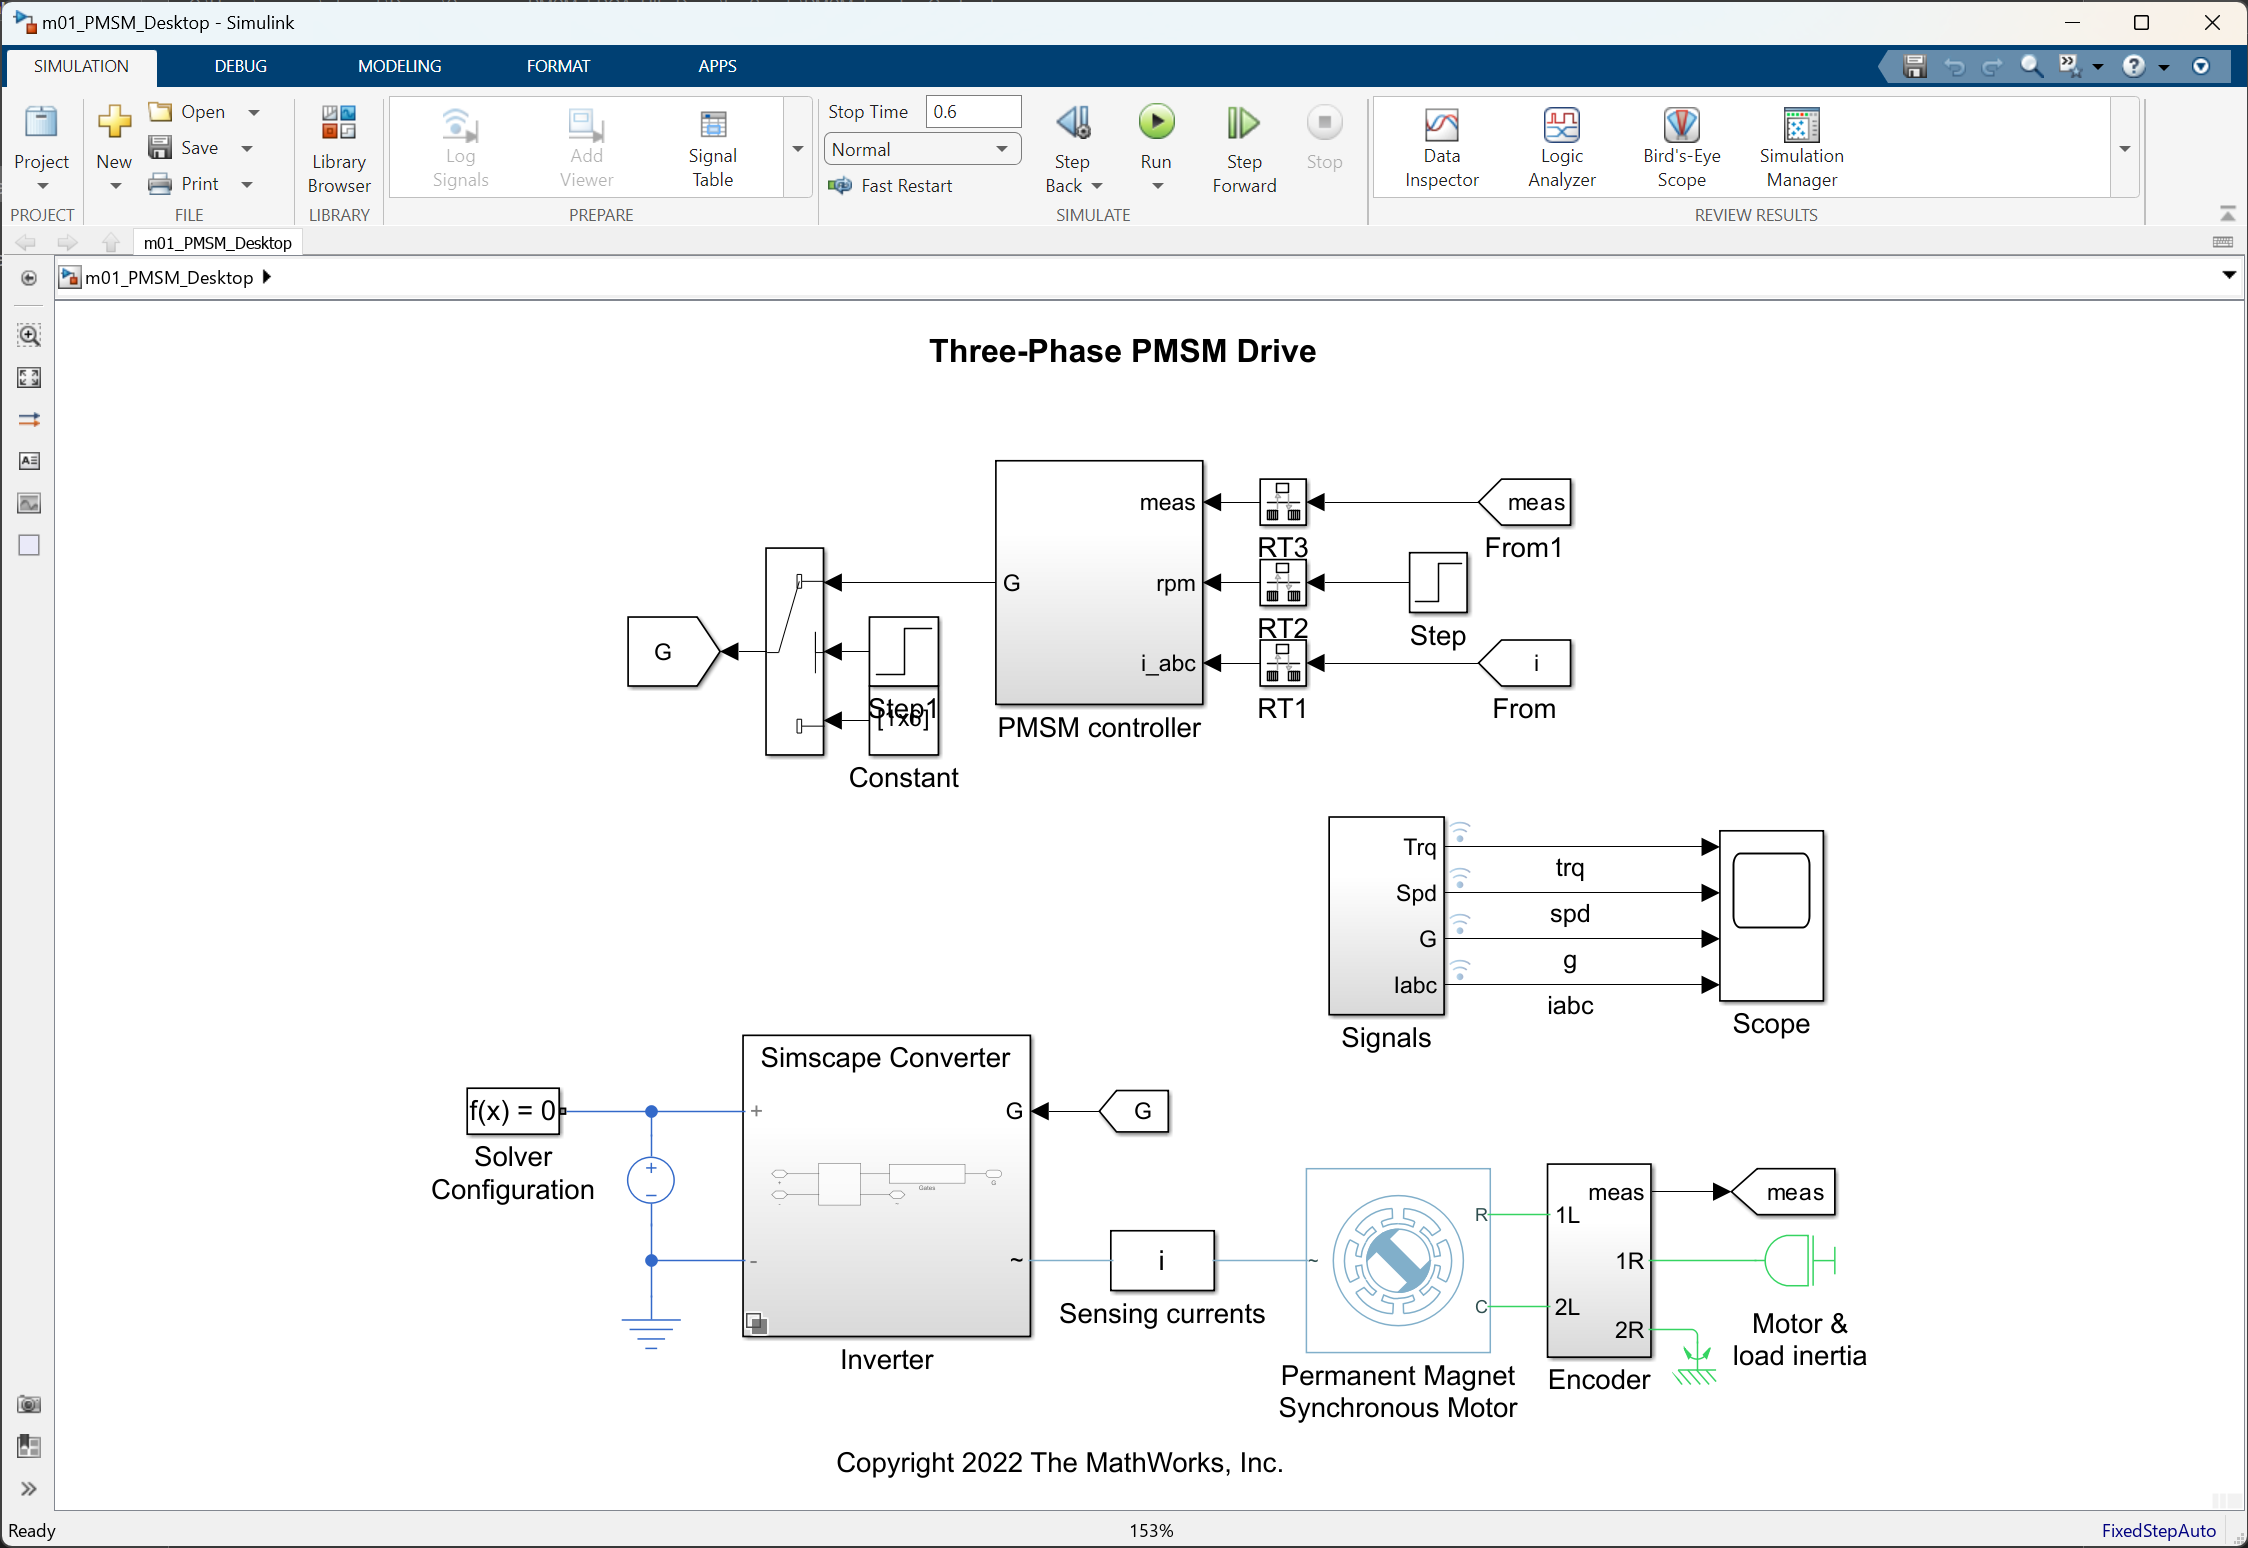

mdlDesktop = 'm01_PMSM_Desktop';
open_system(mdlDesktop);

Please notice that the control logic has also been taken from the same library with the purpose of enabling closed-loop simulation and realistic results but it is out of the scope of this tutorial. More complex motor control logics are likely use in a real use case.

### Simscape Converter

The first simulation is executed with the converter block from the Simscape Electrical library active. This allows us to create reference results we will use later on to compare the required steps we will take to enable HDL code generation from the inverter, and therefore, deployment to an FPGA for real-time simulation.

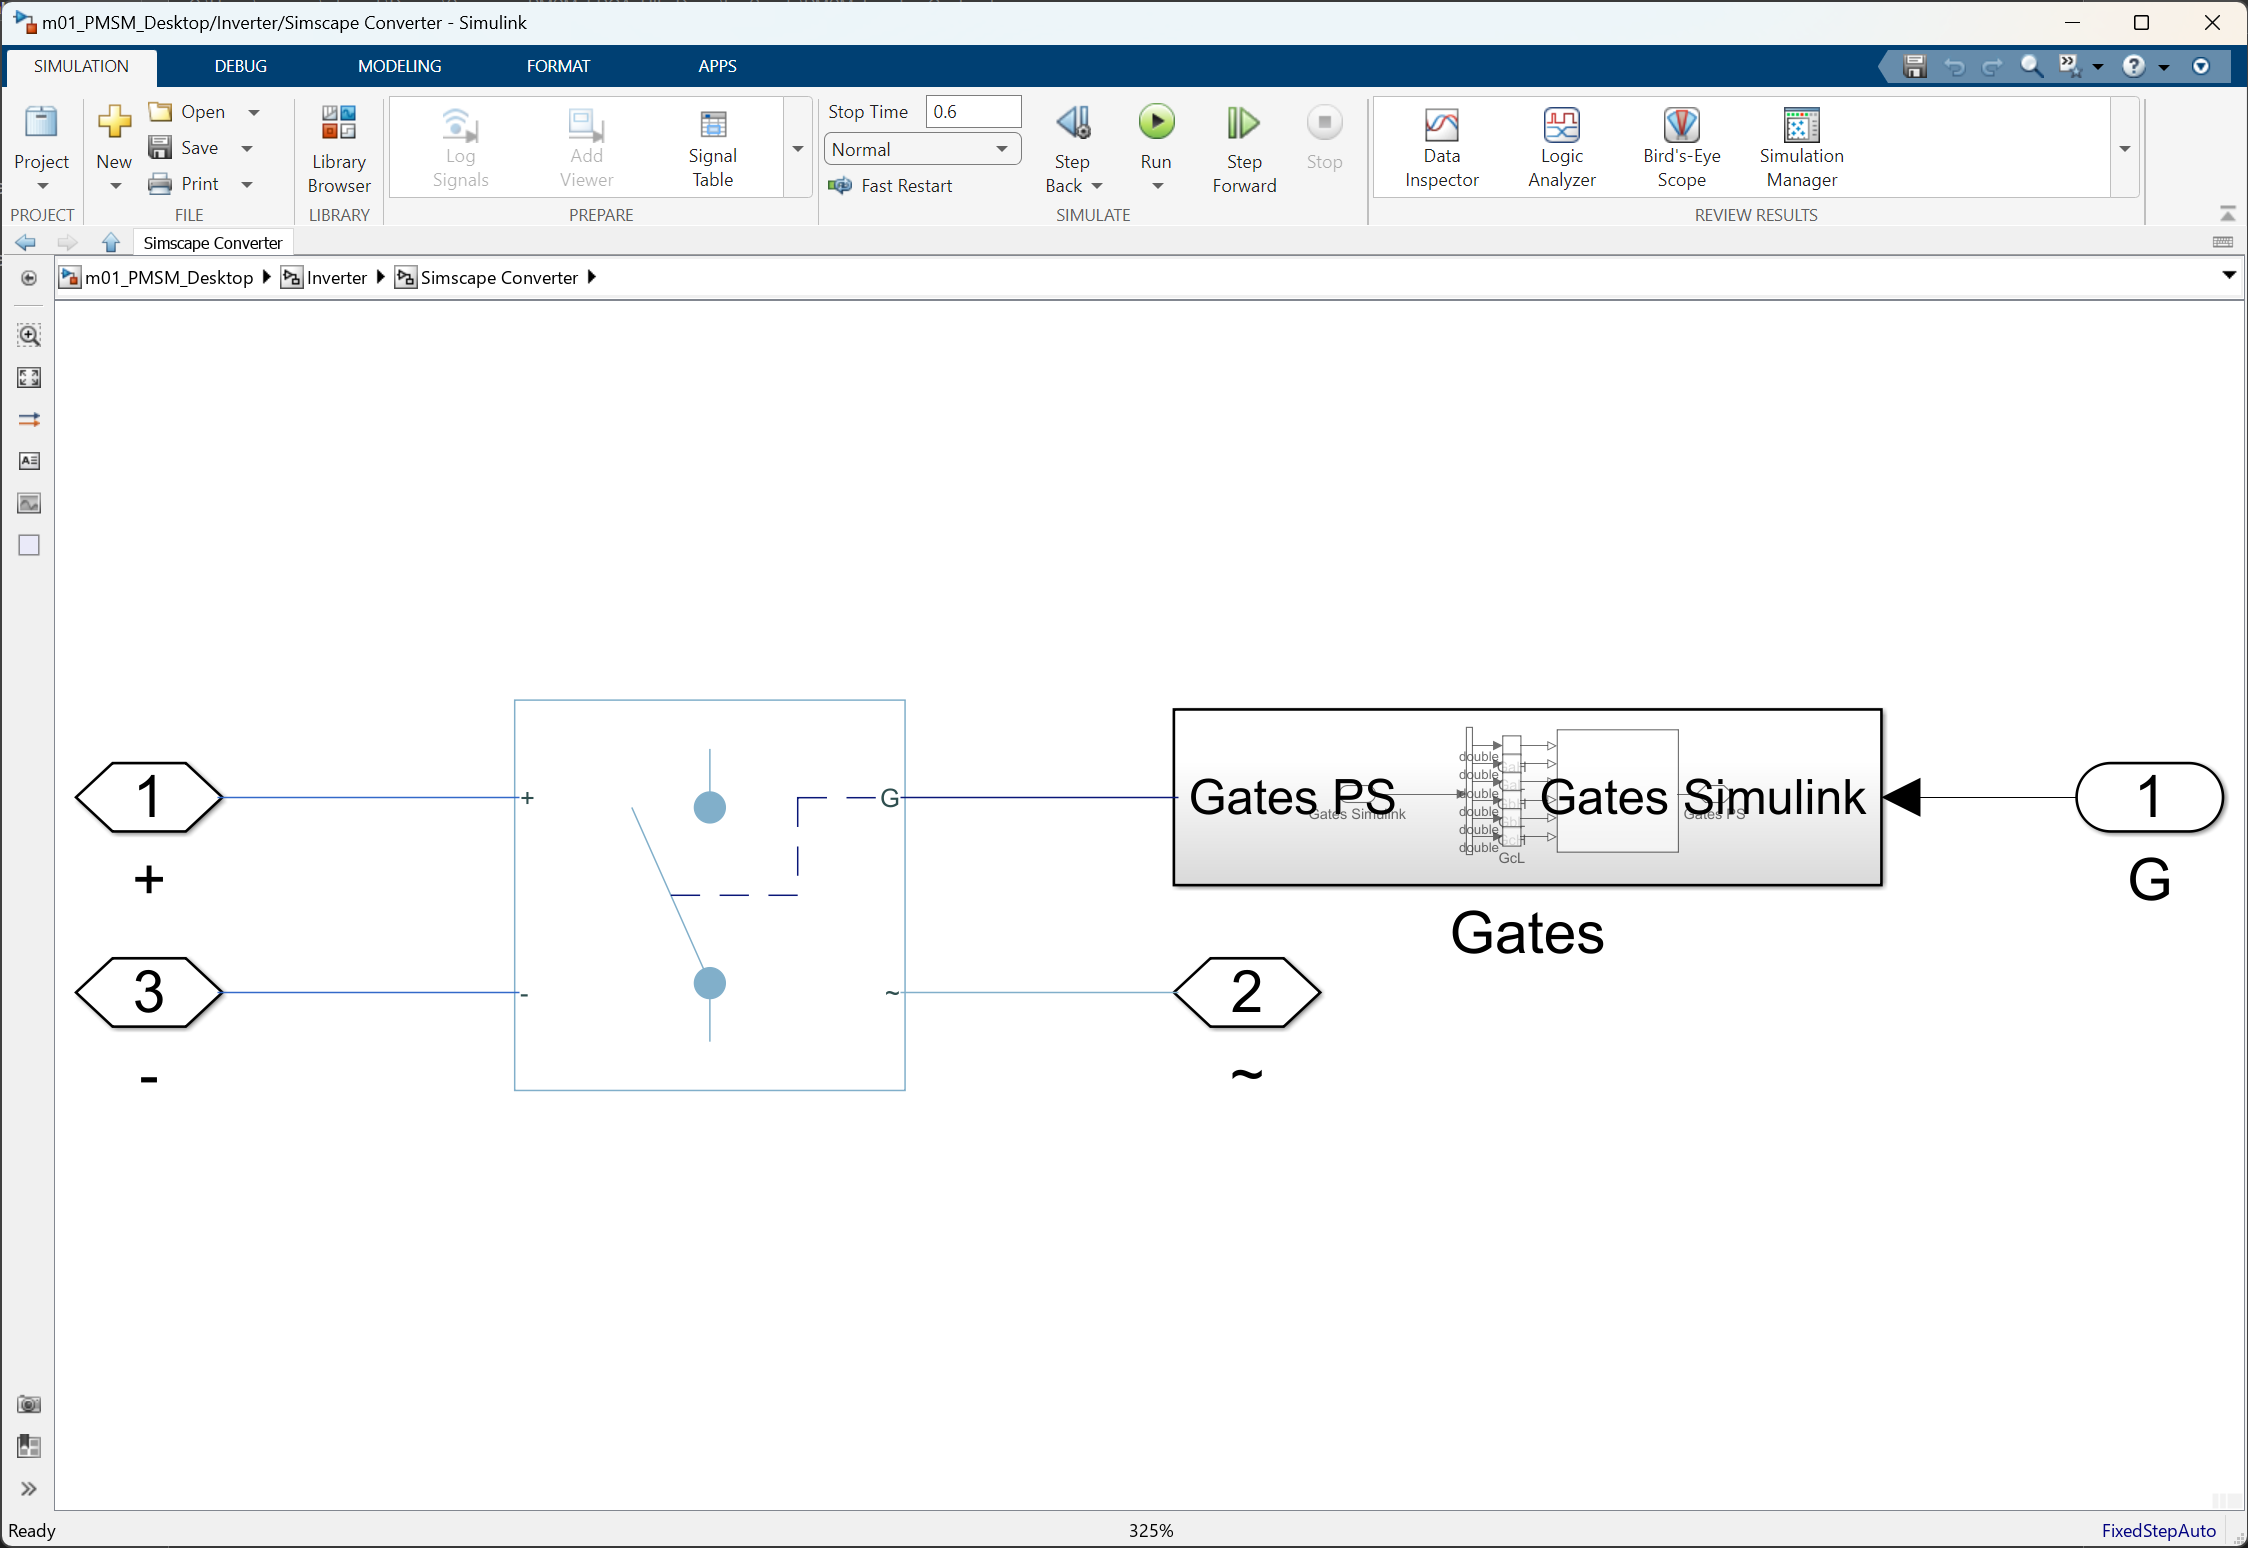

set_param([mdlDesktop,'/Inverter'],'LabelModeActiveChoice','SimscapeConv');
open_system([mdlDesktop,'/Inverter/Simscape Converter']);

We can simulate the model with the current configuration and plot the reference results.

simOutConv = sim(mdlDesktop);

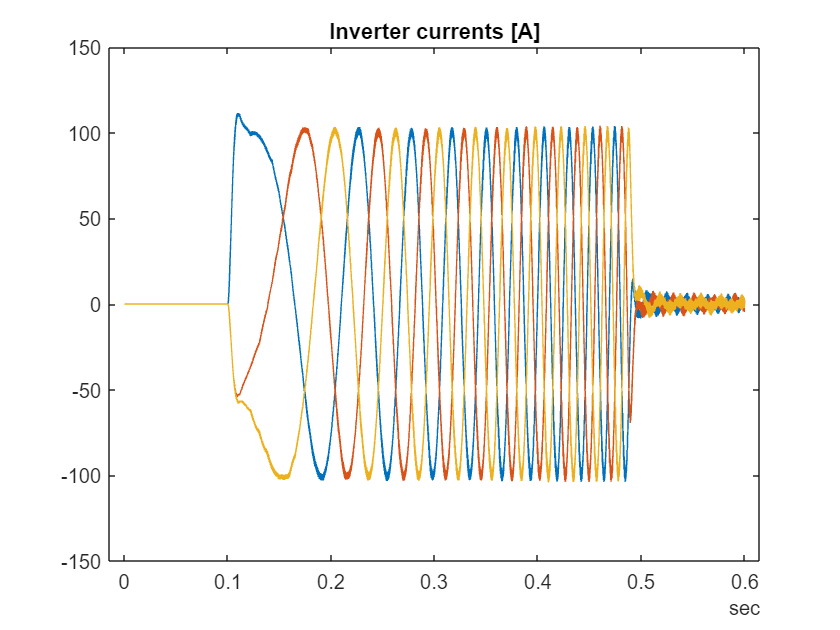

data = simOutConv.logsout.getElement('iabc').extractTimetable;
plot(data.Time,data.Variables);
title('Inverter currents [A]');

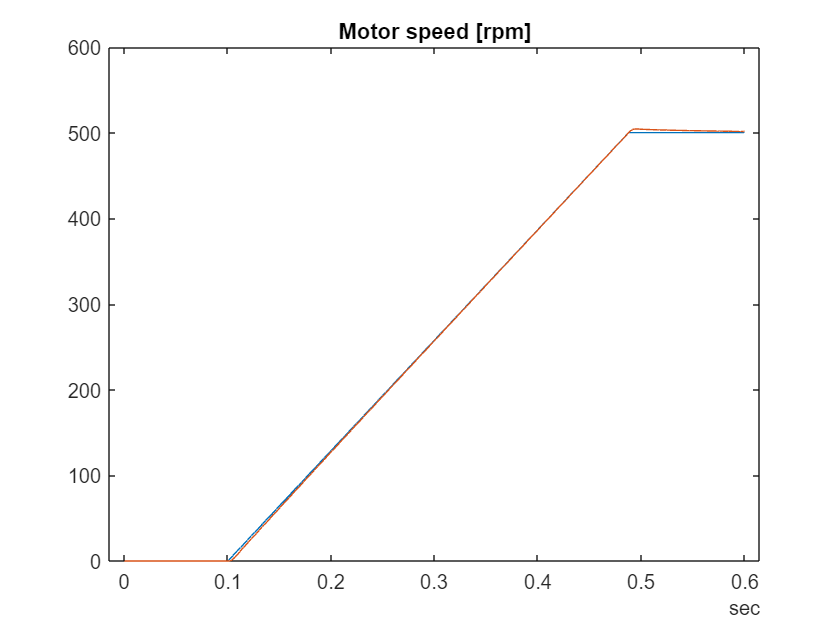

data = simOutConv.logsout.getElement('spd').extractTimetable;
plot(data.Time,data.Variables);
title('Motor speed [rpm]');

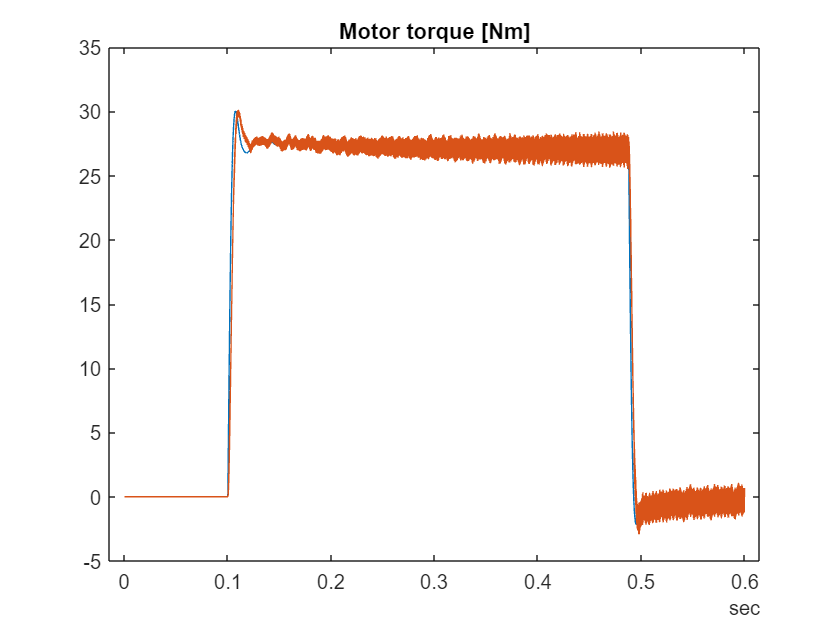

data = simOutConv.logsout.getElement('trq').extractTimetable;
plot(data.Time,data.Variables);
title('Motor torque [Nm]');

We can see that the motor starts accelerating at 0.1s as commanded and will spin up to 500rpm, when it reaches its end target speed. This shows the proper macroscopic behavior, which in many cases is useful for instance to validate controls. However, in the time scopes it's hard to see the effect of the switching devices. Let's take a closer look at approximately the middle of the acceleration ramp.

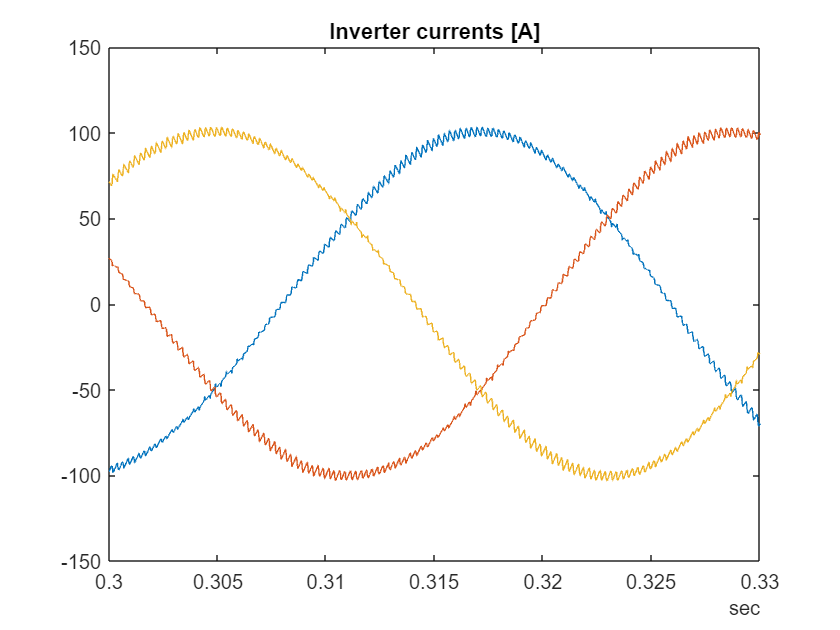

data = simOutConv.logsout.getElement('iabc').extractTimetable;
plot(data.Time, data.iabc);
title('Inverter currents [A]');
xlim([duration(0,0,0.300) duration(0,0,0.33)]);

Please notice that zooming in the time axes allow us to see the current ripple as a consequence of the switching. This is the main effect we want to keep as we move towards an HDL-ready implementation, because it is the direct consequence of the gate commands that our HIL platform will capture and it's intended to validate. Any trade-off or simplification we may apply to the model must be able to reproduce the switching dynamics with a certain level of fidelity (being able to represent the main order armonics).

### Simscape Switches

The converter block we used above is equivalent to its representation with single switches as shown in this step. Sometimes, we may want to use switches instead of an off-the-shelf block for a more explicit modelling approach, when we want to represent slightly different variations of the standard converter topology or for arbitrary reasons.

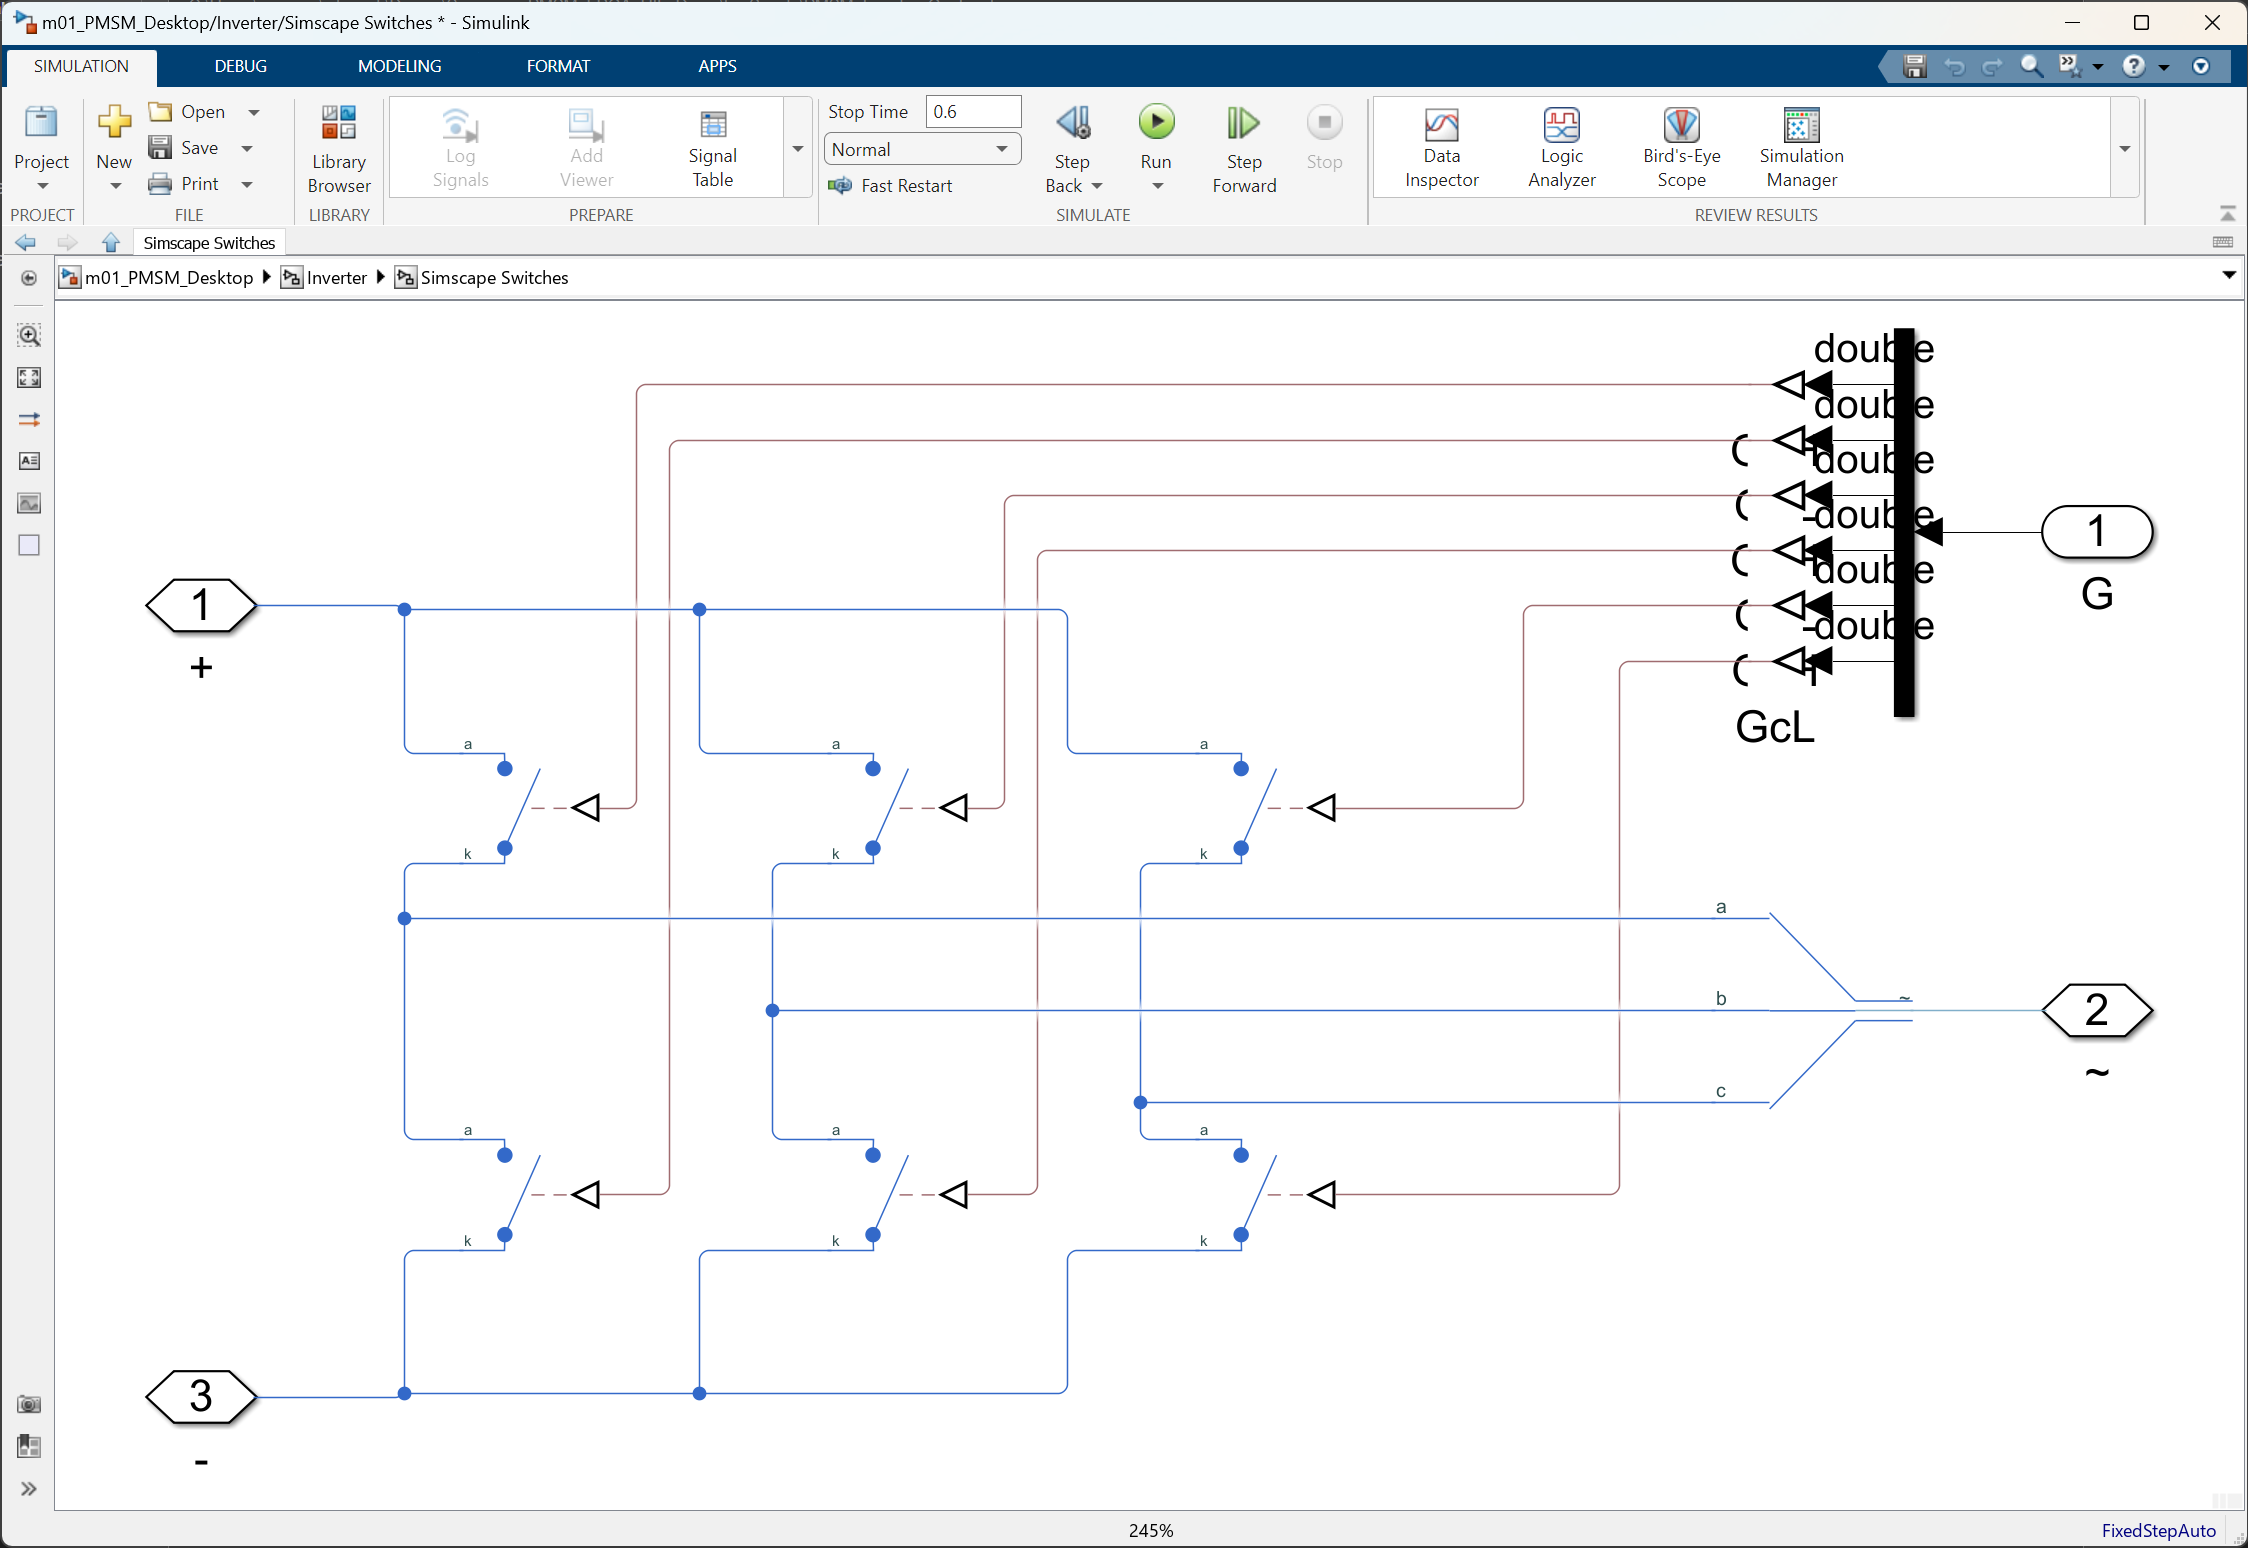

set_param([mdlDesktop,'/Inverter'],'LabelModeActiveChoice','SimscapeSw');
open_system([mdlDesktop,'/Inverter/Simscape Switches']);
simOutSw = sim(mdlDesktop);

Please notice that if the level of fidelity and parameter values are consistent between both representations, the results must be identical.

data = simOutSw.logsout.getElement('iabc').extractTimetable;
plot(data.Time,data.Variables);
title('Inverter currents [A]');

data = simOutSw.logsout.getElement('spd').extractTimetable;
plot(data.Time,data.Variables);
title('Motor speed [rpm]');

data = simOutSw.logsout.getElement('trq').extractTimetable;
plot(data.Time,data.Variables);
title('Motor torque [Nm]');

data = simOutSw.logsout.getElement('iabc').extractTimetable;
plot(data.Time, data.iabc);
title('Inverter currents [A]');
xlim([duration(0,0,0.300) duration(0,0,0.33)]);

### Pejovic Approximation

One of the main benefits of using single switches is that it gives a better foundation when we apply numerical approximations that replace acausal switching devices with mathematical expressions, which are more computationally efficient. Among different techniques the Pejovic approximation is the most well-known and the suggested approach in this tutorial. Please see [Pejovic's paper](https://ieeexplore.ieee.org/document/318904) for further technical reference.

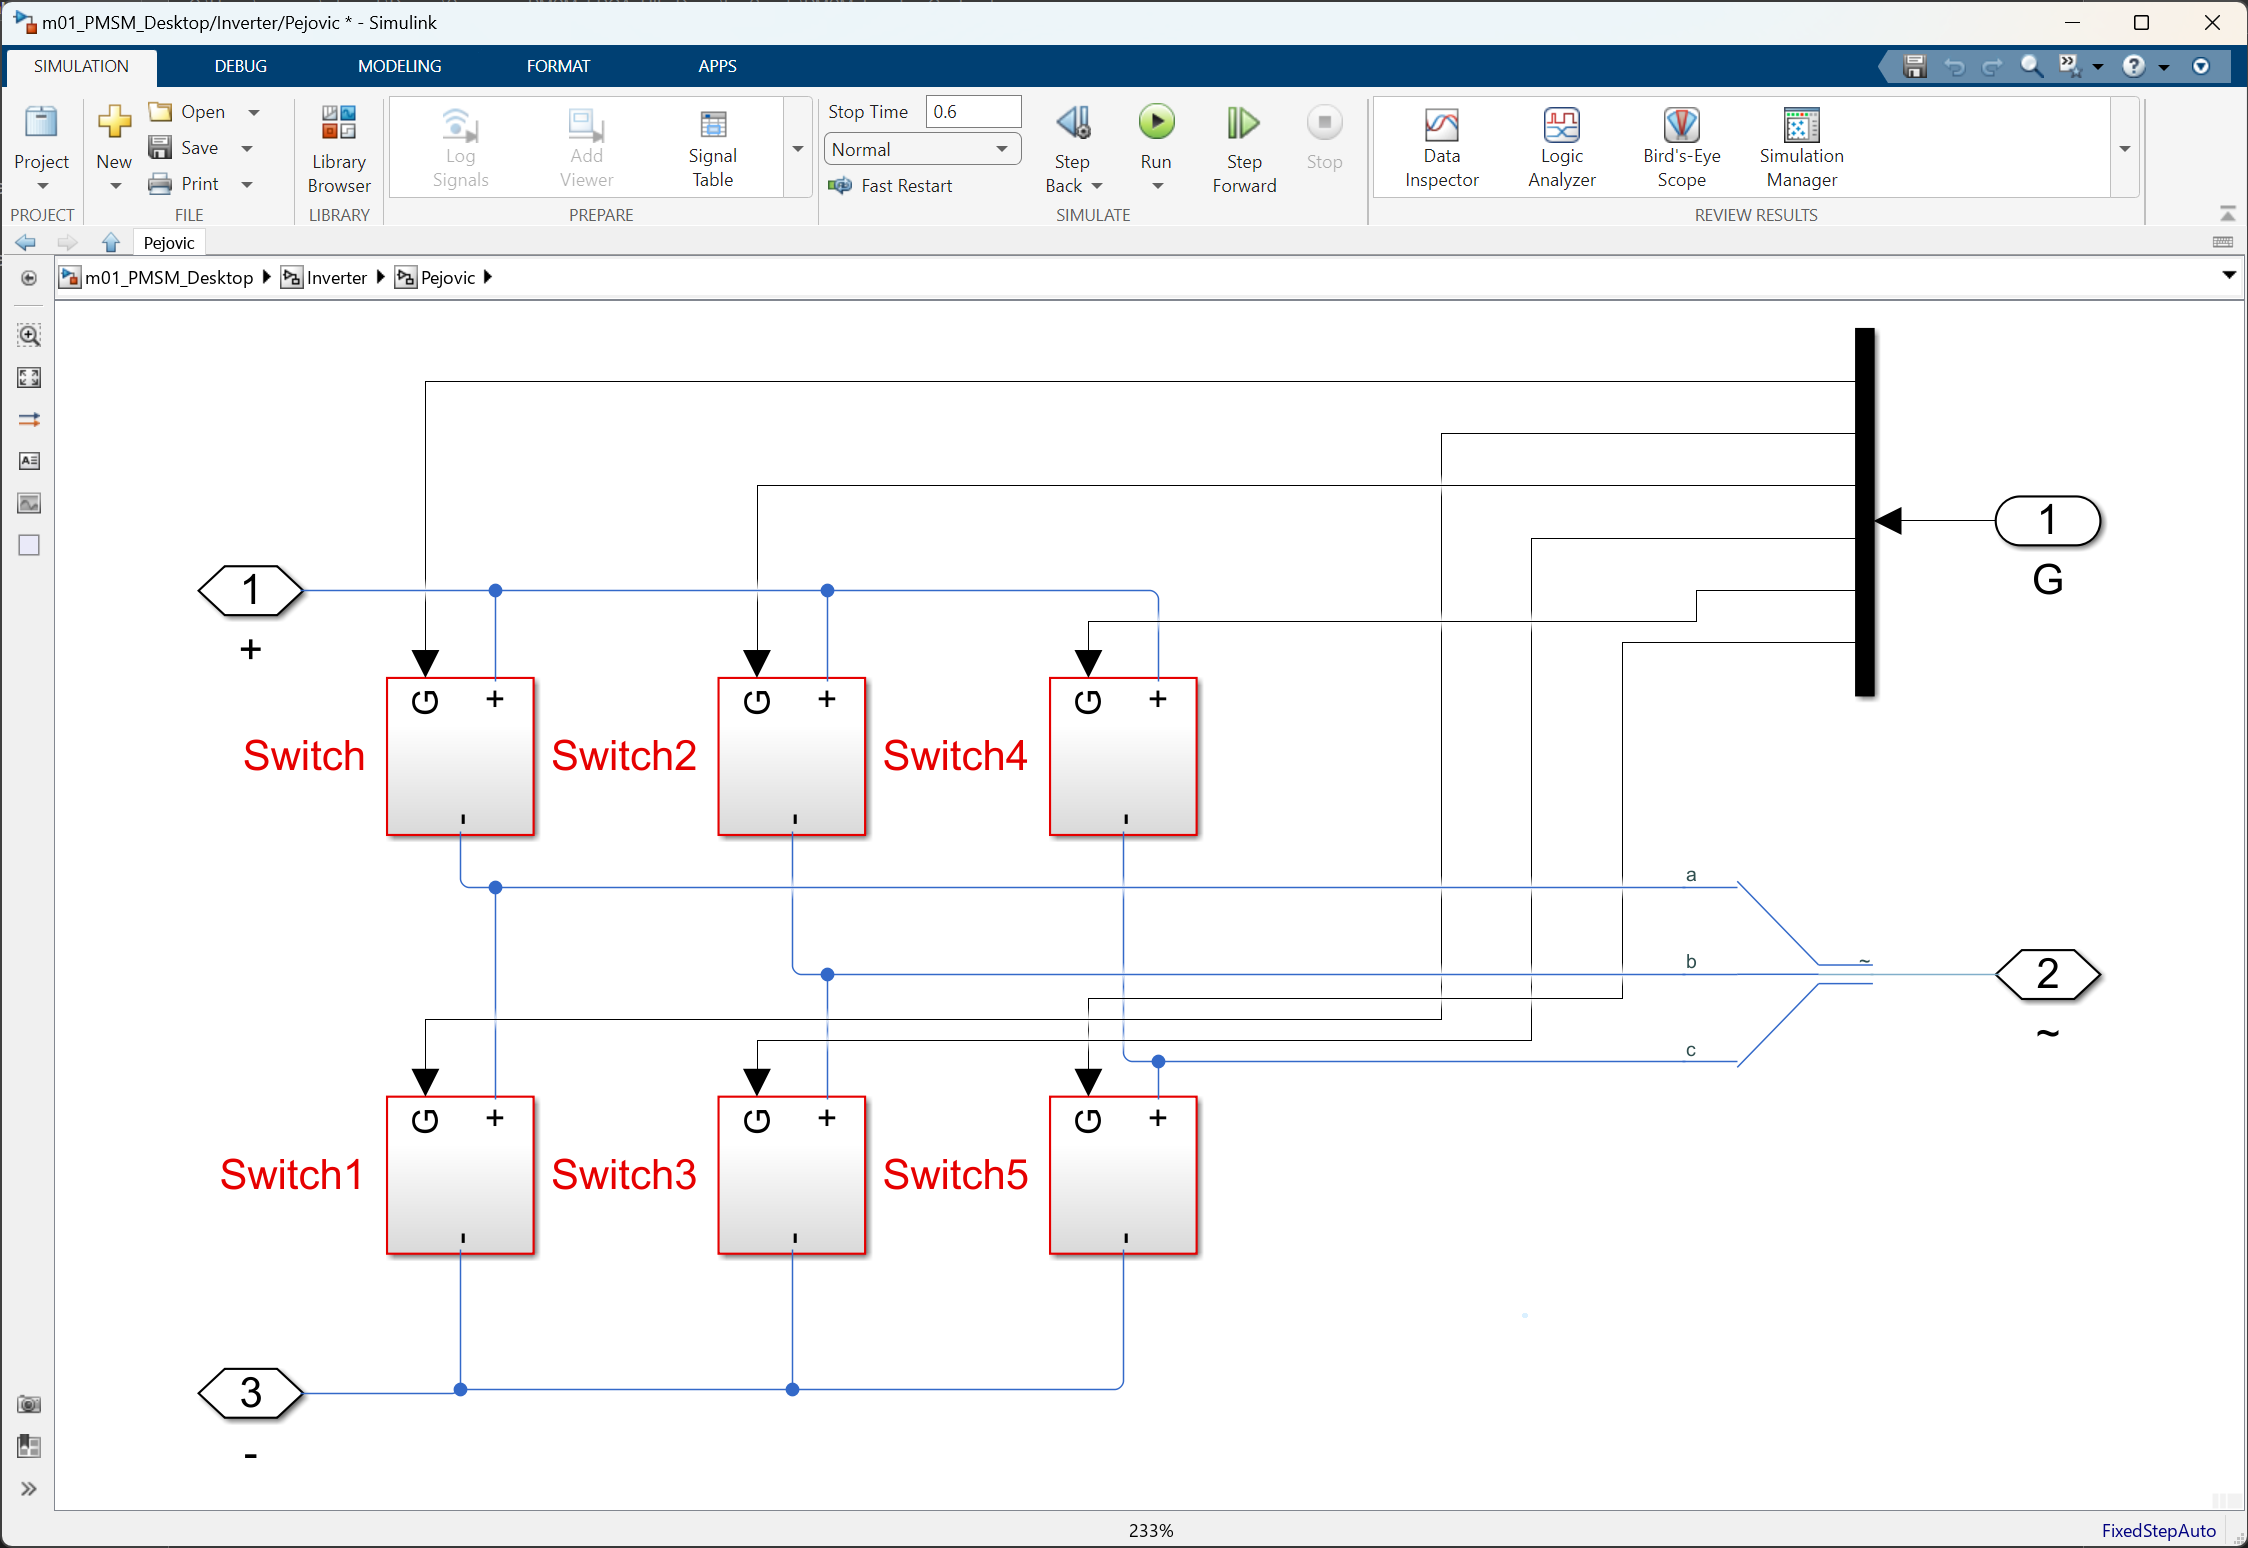

set_param([mdlDesktop,'/Inverter'],'LabelModeActiveChoice','Pejovic');
open_system([mdlDesktop,'/Inverter/Pejovic']);

This approximation consists on replacing every component on a Simscape network with two states such an ideal switch or a diode, with a Simulink-based implementation that computes the current based on the gate command and injects it back into the Simscape network.

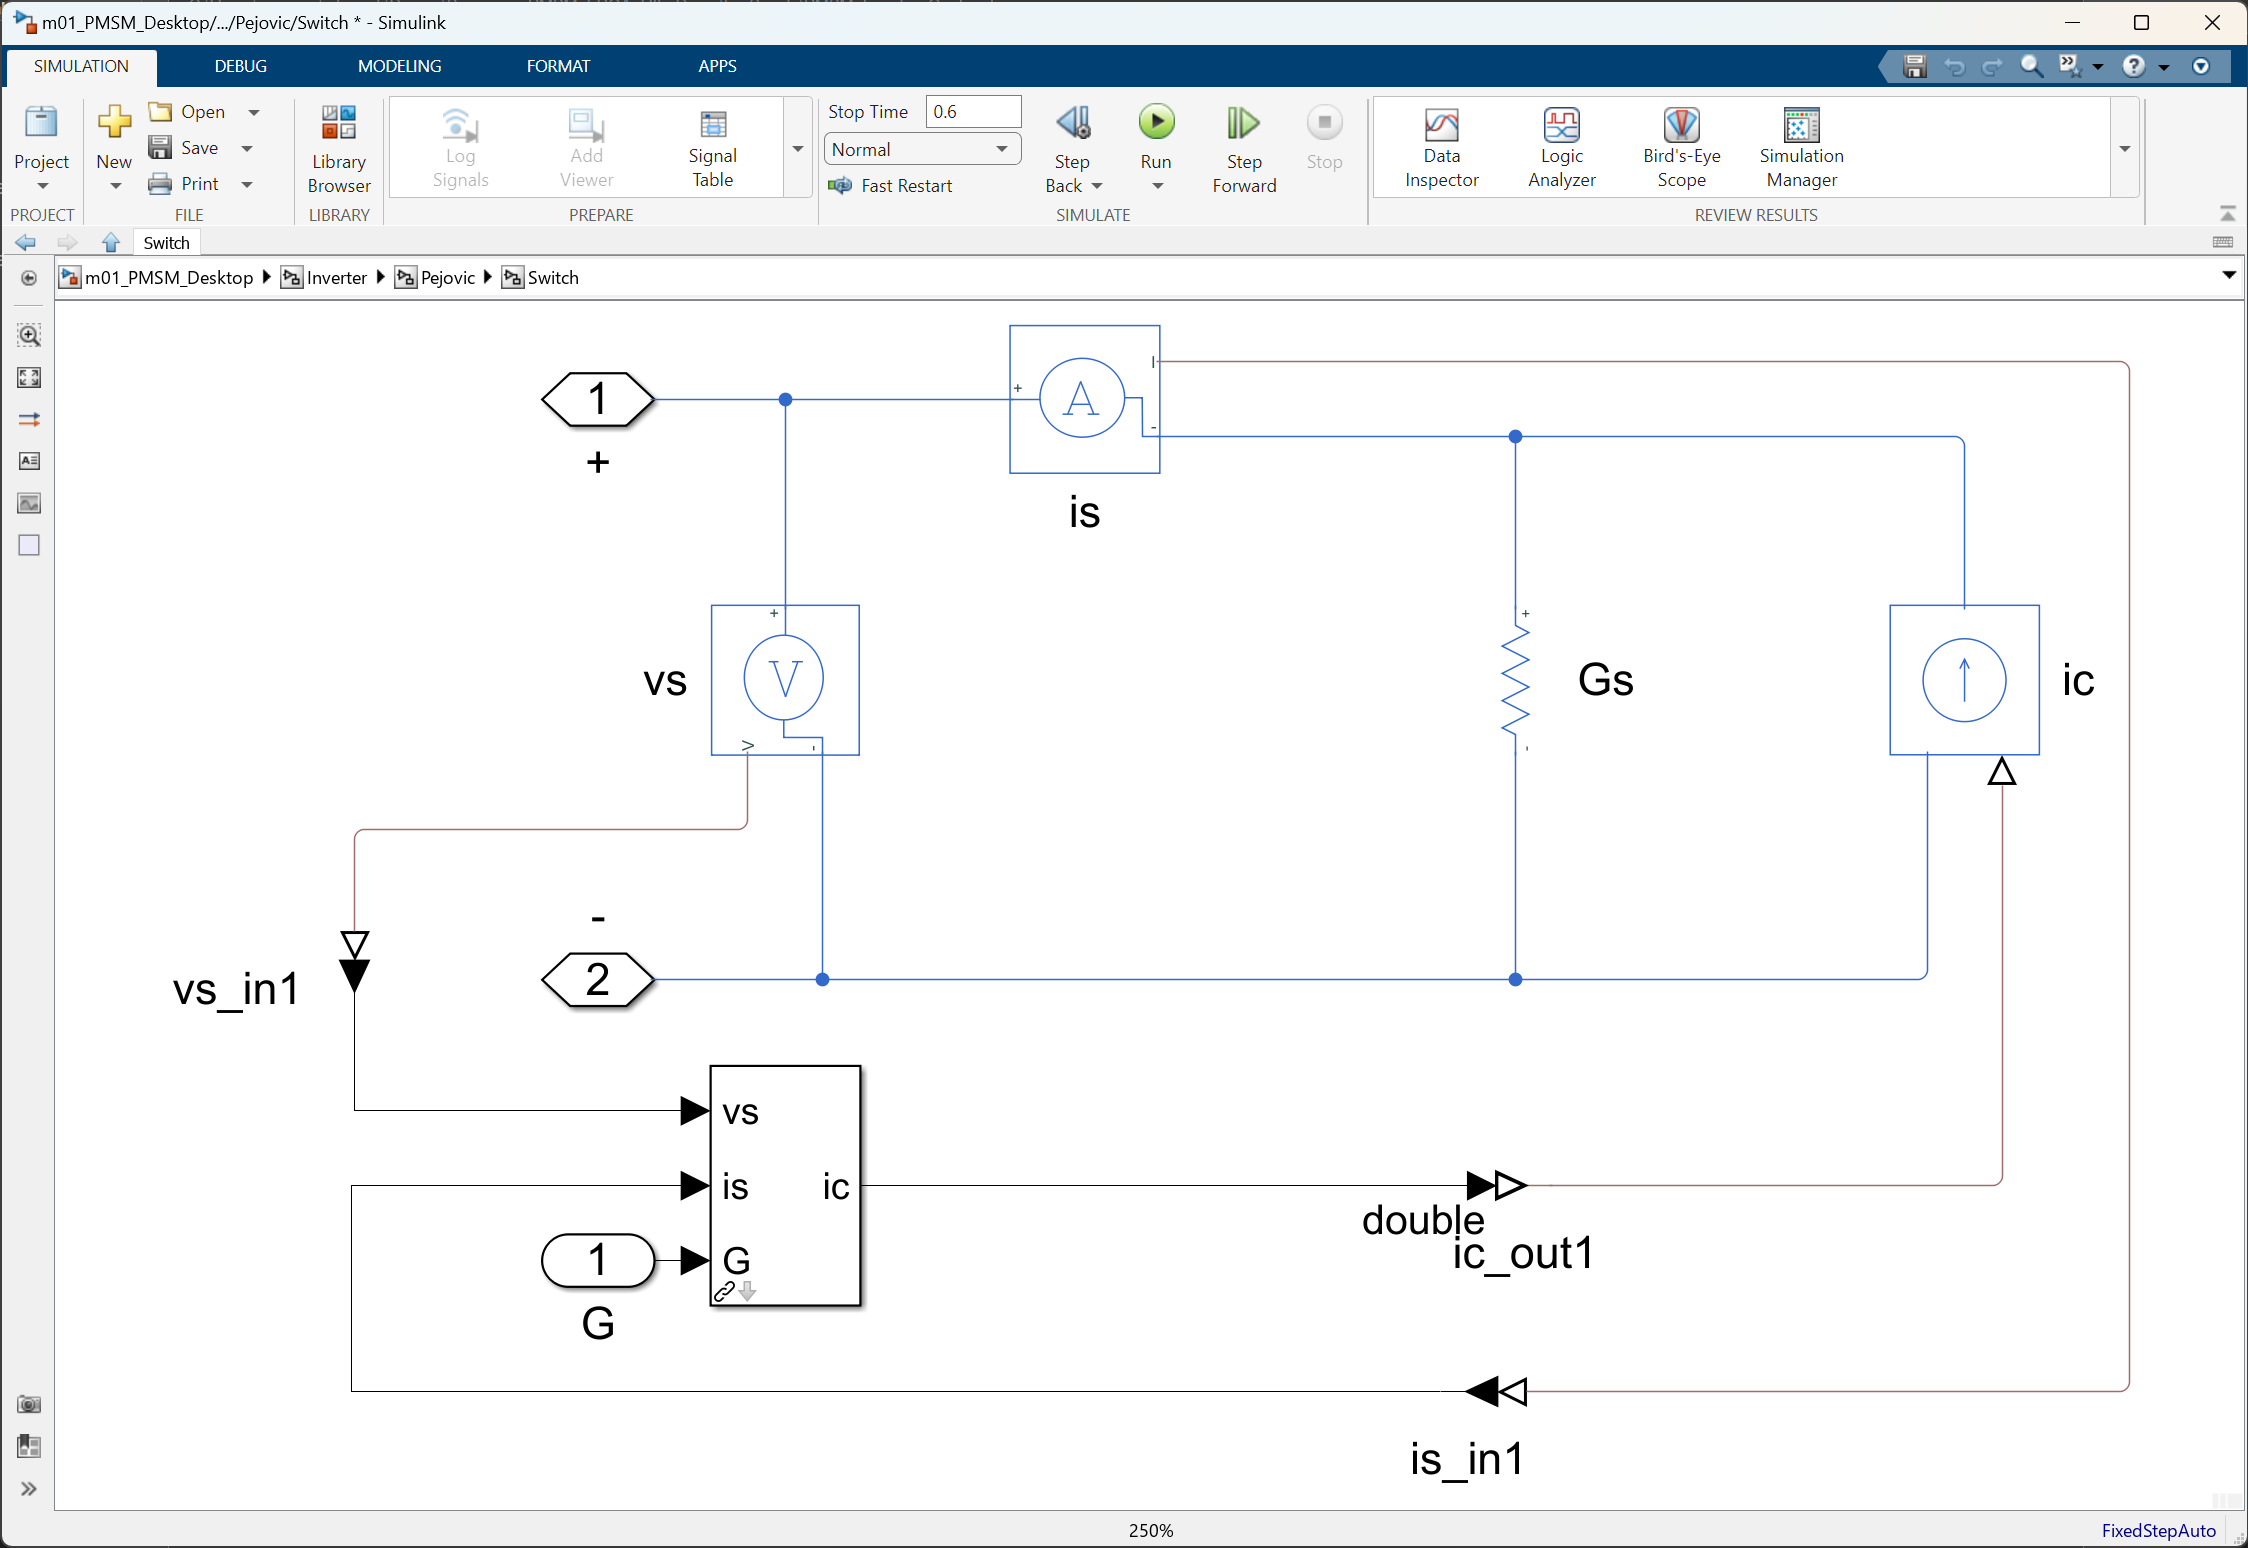

open_system([mdlDesktop,'/Inverter/Pejovic/Switch1'],'force');

For ease of use, MATLAB ships a library containing the numerical approximations for the most common electrical devices that can be replaced with its Pejovic approximation.

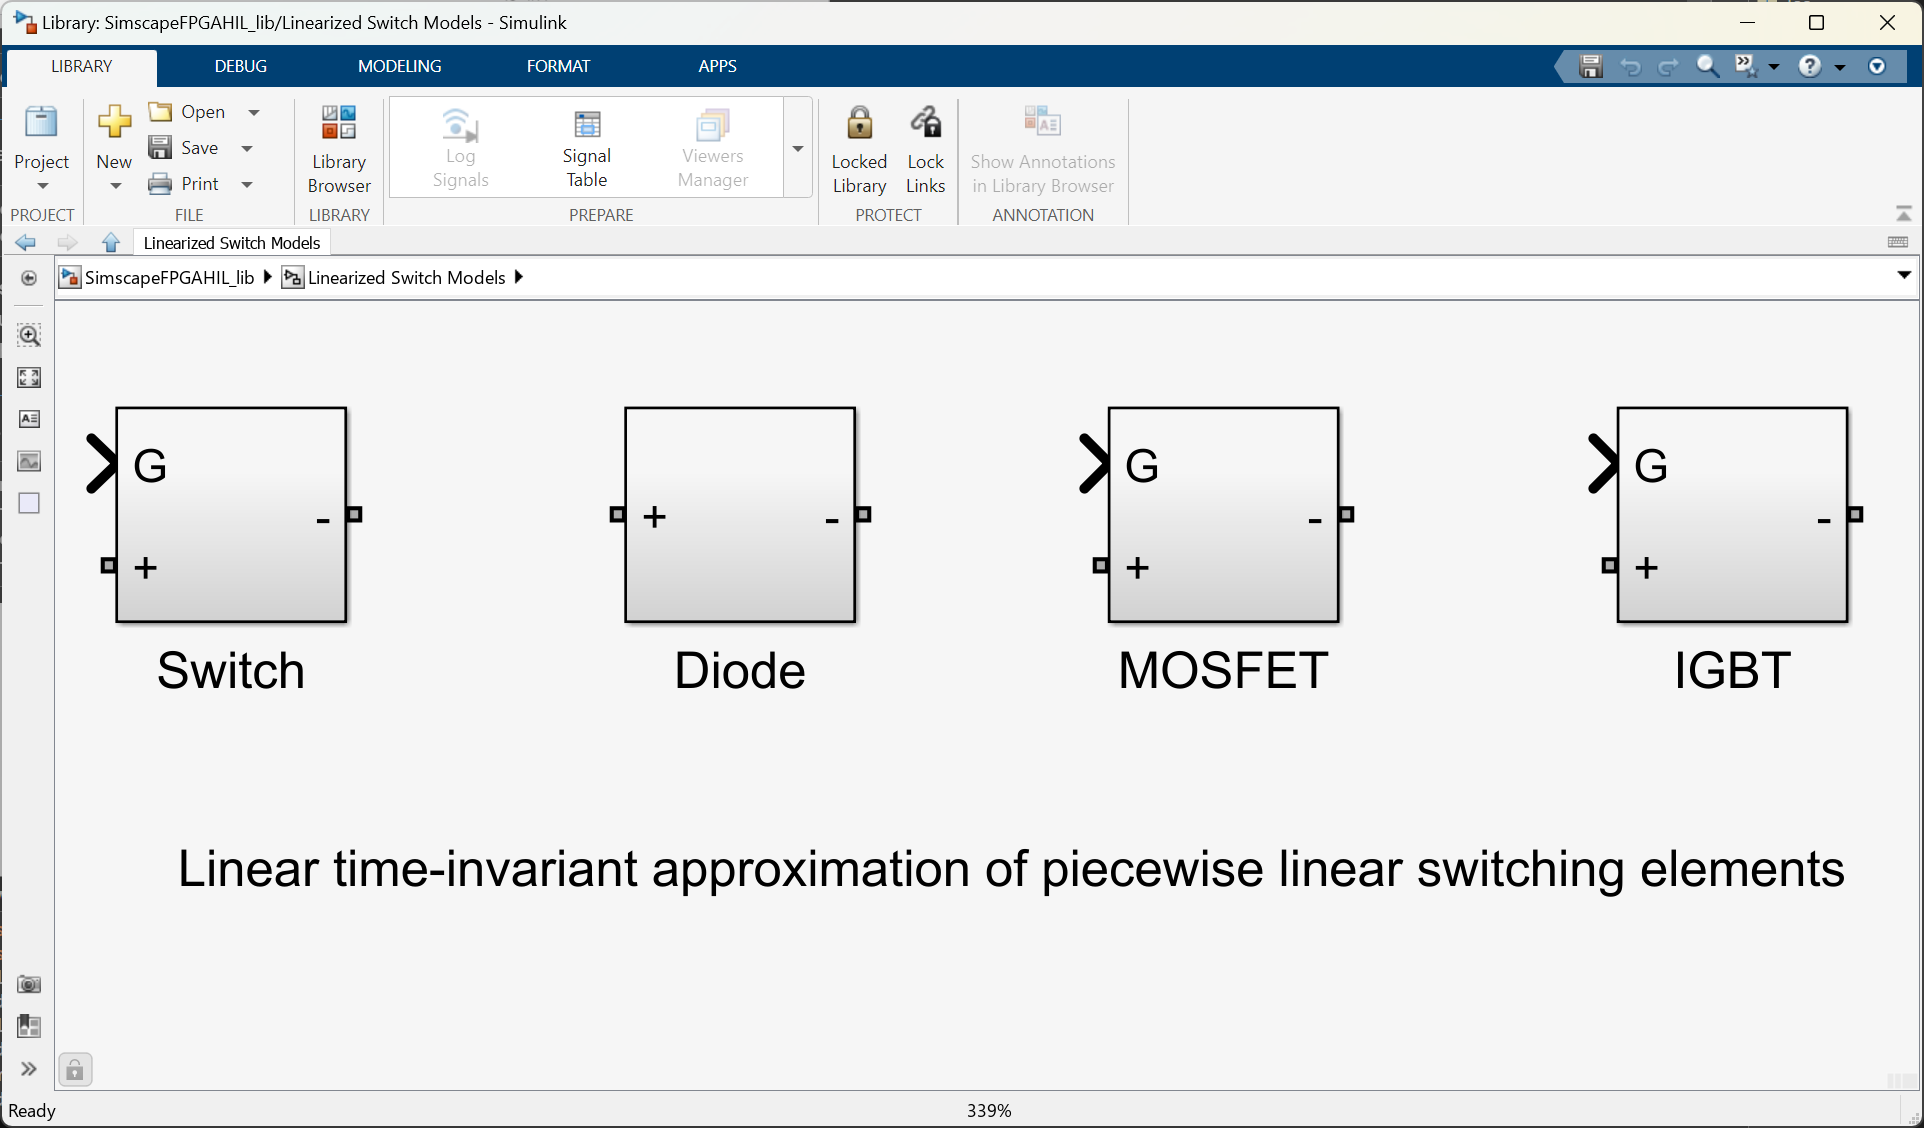

open_system('SimscapeFPGAHIL_lib');
open_system('SimscapeFPGAHIL_lib/Linearized Switch Models');

Please notice that the Simulink-based approximation contains some numerical parameters that can be tuned to increase the accuracy of the Pejovic approximation. Other than manual parameter tuning, the suggested method to figure out the best set of values is using the golden reference model with the actual Simscape switches to create synthetic data, which we can later feed into the [Parameter Estimation app](matlab:web(fullfile(docroot, 'sldo/gs/estimate-parameters-from-measured-data-using-the-gui.html'))) to let Simulink automatically optimize and converge to the values delivering the closest results to the original reference.

Let's run the approximated inverter model with the Pejovic approximation and plot the results.

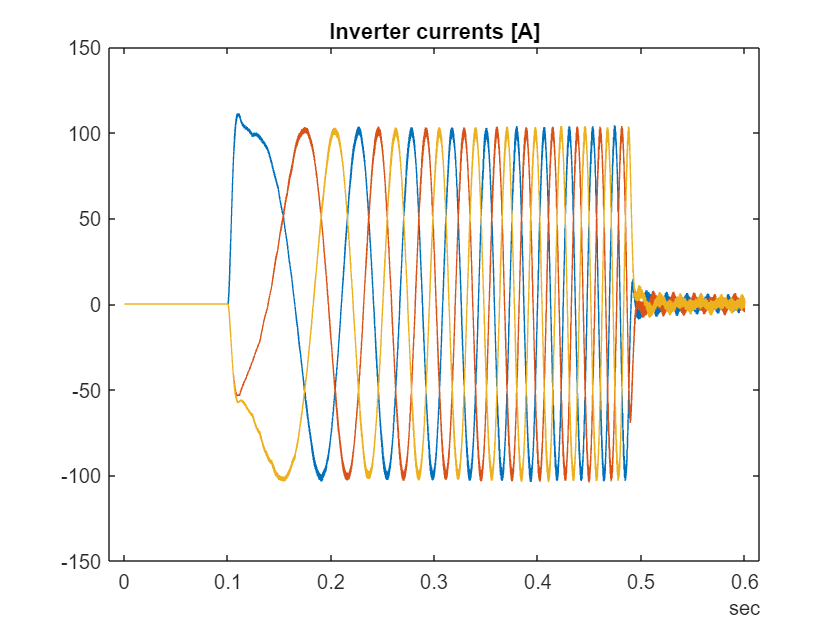

simOutPej = sim(mdlDesktop);
data = simOutPej.logsout.getElement('iabc').extractTimetable;
plot(data.Time,data.Variables);
title('Inverter currents [A]');

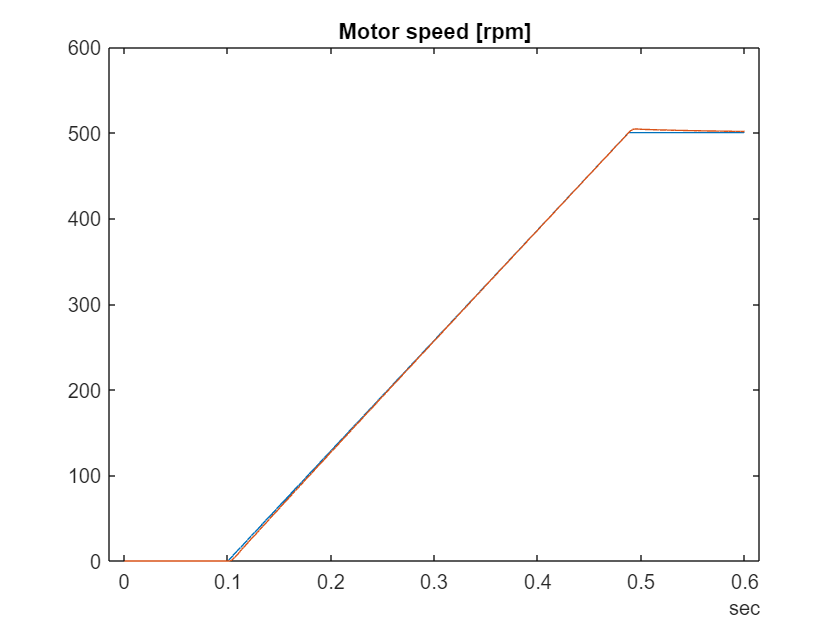

data = simOutPej.logsout.getElement('spd').extractTimetable;
plot(data.Time,data.Variables);
title('Motor speed [rpm]');

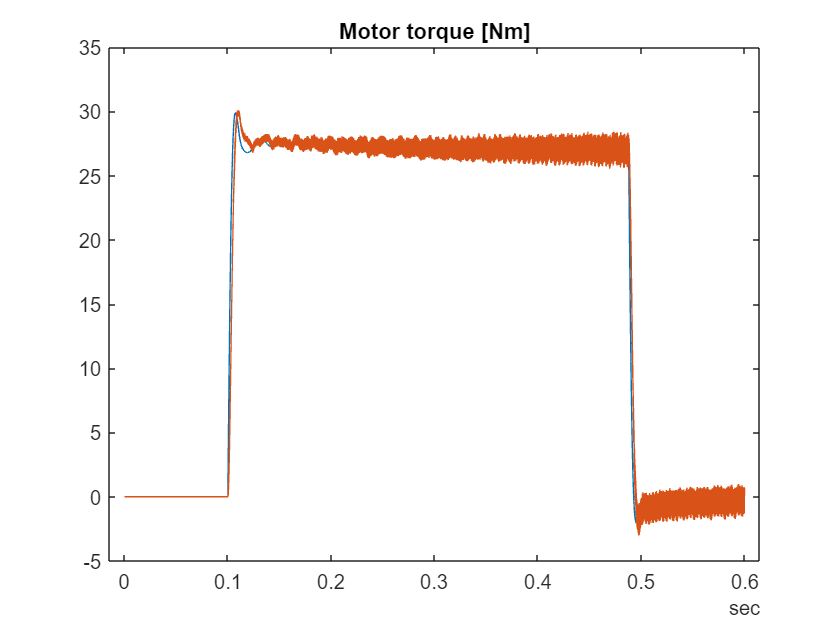

data = simOutPej.logsout.getElement('trq').extractTimetable;
plot(data.Time,data.Variables);
title('Motor torque [Nm]');

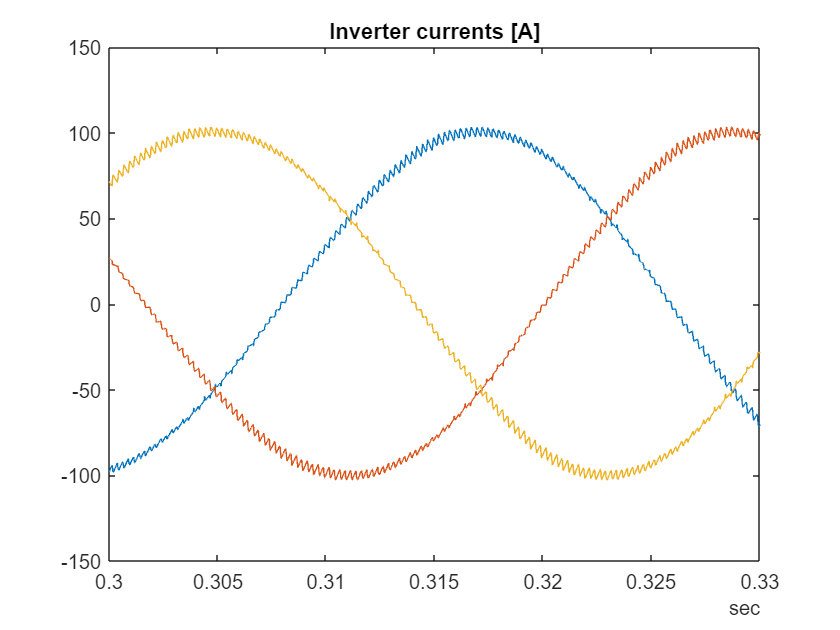

data = simOutPej.logsout.getElement('iabc').extractTimetable;
plot(data.Time, data.iabc);
title('Inverter currents [A]');
xlim([duration(0,0,0.300) duration(0,0,0.33)]);

In addition, we can compare results from the last two simulations to validate our approach using the Pejovic approximation.

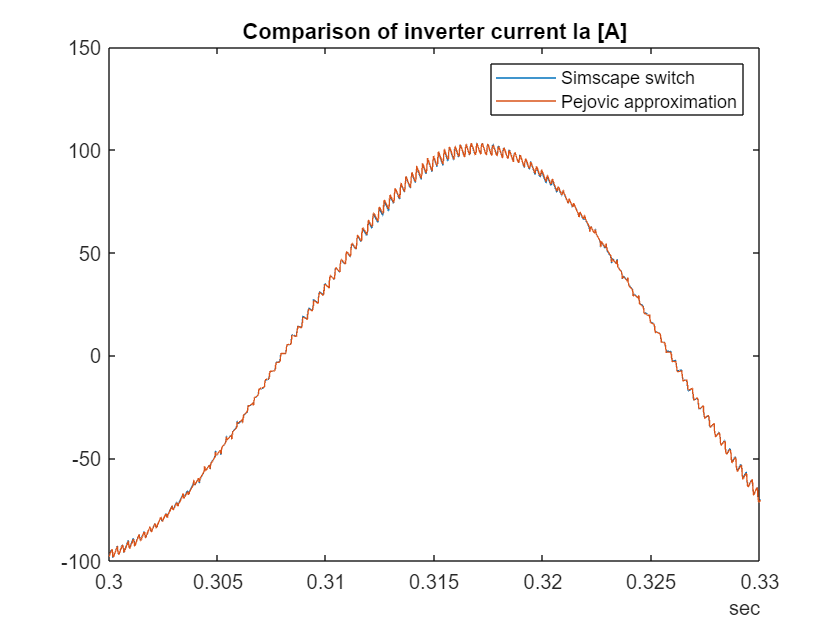

iabcPej = simOutPej.logsout.getElement('iabc').extractTimetable;
iabcSw = simOutSw.logsout.getElement('iabc').extractTimetable;
plot(data.Time, iabcSw.iabc(:,1),...
    data.Time, iabcPej.iabc(:,1));
title('Comparison of inverter current Ia [A]');
legend('Simscape switch','Pejovic approximation');
xlim([duration(0,0,0.300) duration(0,0,0.33)]);

Please notice how the Pejovic approximation is able to match the accuracy of the current ripple required for HIL tests, while it allows a much more efficient FPGA implementation as we will see in the next chapter.

## Simscape to HDL-ready model conversion

In contrast to C and C++ code generation that is very versatile and widely supported by many Simulink blocks and designs, automatic HDL code generations has stronger requirements with respect of model topologies and blocks supported. In a few words, we cannot generate HDL code (required before synthesis of an FPGA bitstream) directly from a Simscape model. We must create an equivalent representation to our source Simscape model that captures the same physical behavior but supports HDL code generation.

Since HDL code generation is fundamentally based on Simulink blocks, our eventual representation that supports this new method to generate HDL code is likely to be Simulink-based. Our best bet is to convert the Simscape network, which is an acausal model, to a state-space representation whose matrix coefficients vary based on every network's mode. This is the main goal of the Simscape to HDL Workflow Advisor.

Simscape to HDL Worflow Advisor requires a Simscape local solver to run: either backward Euler for switched-linear models (those made up exclusively of linear components such as resistors or capacitors, and switching devices), or partitioning solver for non-linear models (those containing also non-linear components such as a PMSM). In this model, we have therefore selected the partitioning solver.

### Standard approach

Our first guess is very likely to apply the Simscape to HDL Workflow Advisor on a standard Simscape model such as the one we have at the beginning with off-the-shelf Simscape library blocks for the converters and switching devices.

open_system(mdlDesktop);
set_param([mdlDesktop,'/Inverter'],'LabelModeActiveChoice','SimscapeConv');

To start the Simscape to HDL Workflow Advisor, we must run the corresponding command in the console.

sschdladvisor(mdlDesktop);

### Running Simscape HDL Workflow Advisor for m01_PMSM_Desktop


Please run the two first level conversion steps and observe the results. Simulink will observe, extract and compute the modes and the state-space matrixes that are activated at some point during the current simulation setup. This will allow us to take a snapshot of the system states that are relevant for our application and reuse them later in a Simulink-based implementation.

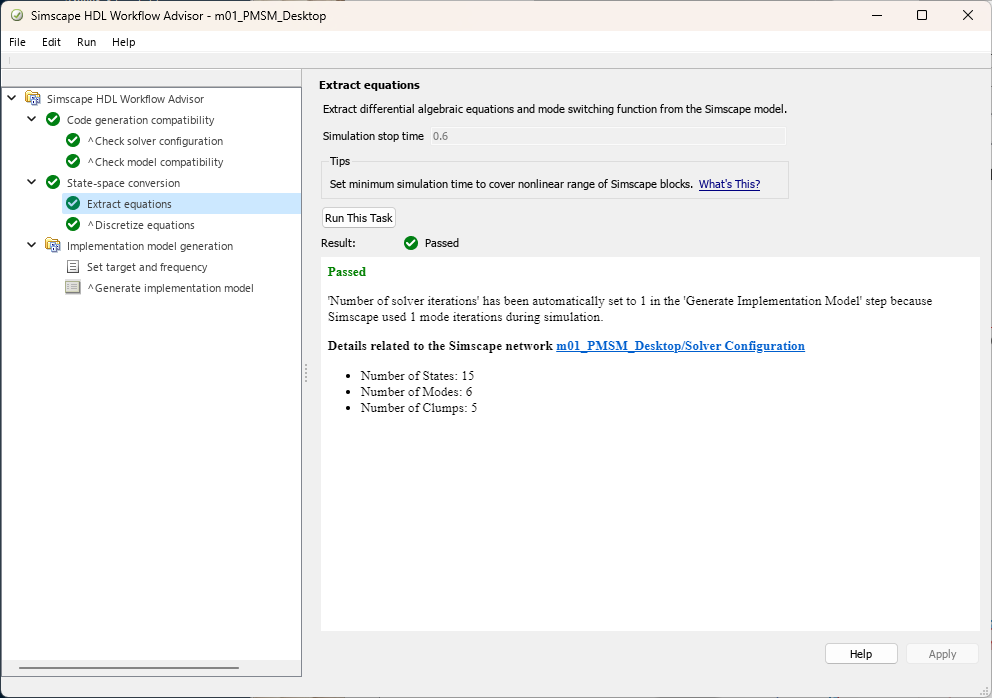

However, this approach implies that any mode that has not been excited during that simulation that the Workflow Advisor runs cannot be consider later in the state-space representation. If for any mean, for instance a different set of inputs, we end up in a different mode that had not been extracted from the Simscape model, the state-space representation may suffer from less accuraccy although a warning will be issued if this case is detected to alert the user, so that a new execution of the Simscape to HDL Workflow Advisor adding this set of inputs and potentially more nodes is carried out.

This process can be a bit cumbersome. Besides, the process to determine the active mode in every moment and the switching modes requires a more sophisticated Simulink state-space model, which may lead to more FPGA resources required. To address both issues, we can use the Pejovic approximation method presented above.

### Optimized approach based on Pejovic approximation

Let's repeat the same process running the Simscape to HDL Workflow Advisor, but now switch to the variant that contains the Pejovic approximation for the switching devices.

open_system(mdlDesktop);
set_param([mdlDesktop,'/Inverter'],'LabelModeActiveChoice','Pejovic');
sschdladvisor(mdlDesktop);

### Running Simscape HDL Workflow Advisor for m01_PMSM_Desktop


If we run the same steps in the workflow than in the previous attempt, we nothce that now there is only one mode being captured. That means that regardless of the gate commands and the open or closed state of the switches, the overall representation of the Simscape network can be represented in one single mode because that switching behavior has been transferred from a Simscape representation to a Simulink-based one. A Simulink representation that is HDL-ready and do not need to be converted before generating HDL code.

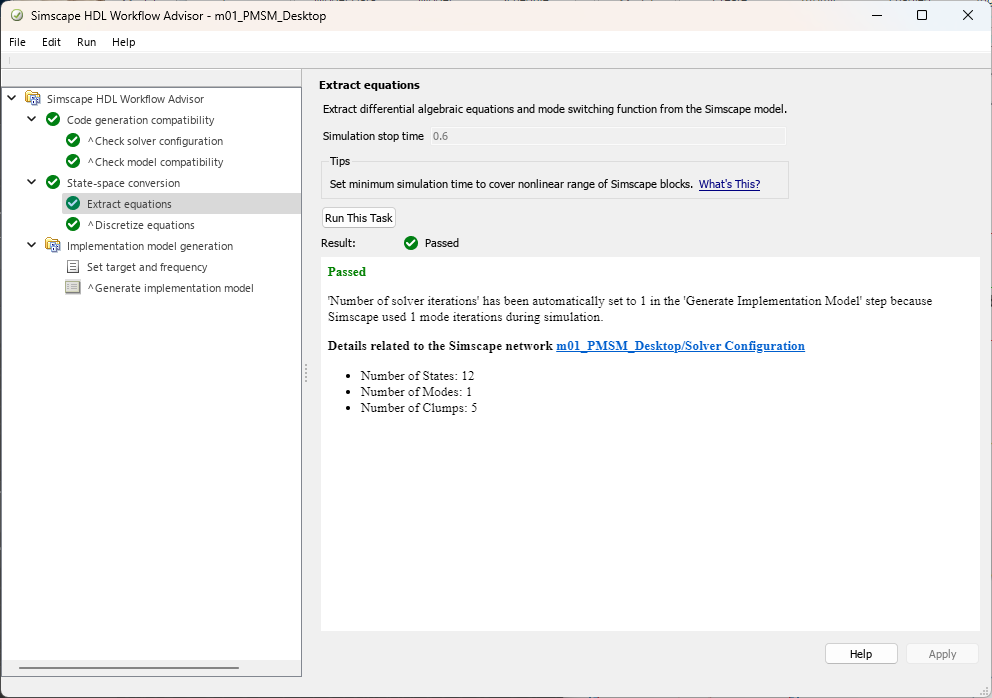

In other words, by replacing the switching devices with a Pejovic approximation, we have converted the initial Simscape model into a Linear Time-Invariant System (LTI), a system that can be represented by one single mode and one single set of state-space matrixes.

With this method, we can be confident that every set of inputs we use to feed the state-space model will be accurately simulated, and we don't need to iterate in the Simscape to HDL conversion process. Besides, the LTI representation leads to simpler HDL code, and therefore, a more efficient FPGA implementation.

Our further work will be basedo on this approach, which is as well the recommended method for any real power electronics application intended to run on a FPGA-based HIL.

We can complete the execution of the Simscape to HDL Workflow Advisor and finally, use the implementation model that state-space representation and Simscape models results match when using identically simulation inputs. This validation step can also be automated setting the validation logic and tolerance on demand.

## State-space representation and HDL code generation

After the successful execution of the Simscape to HDL Workflow Advisor, we can reconstruct our original main model, replacing the Simscape network with the HDL subsystem containing the state-space representation that has been automatically generated.

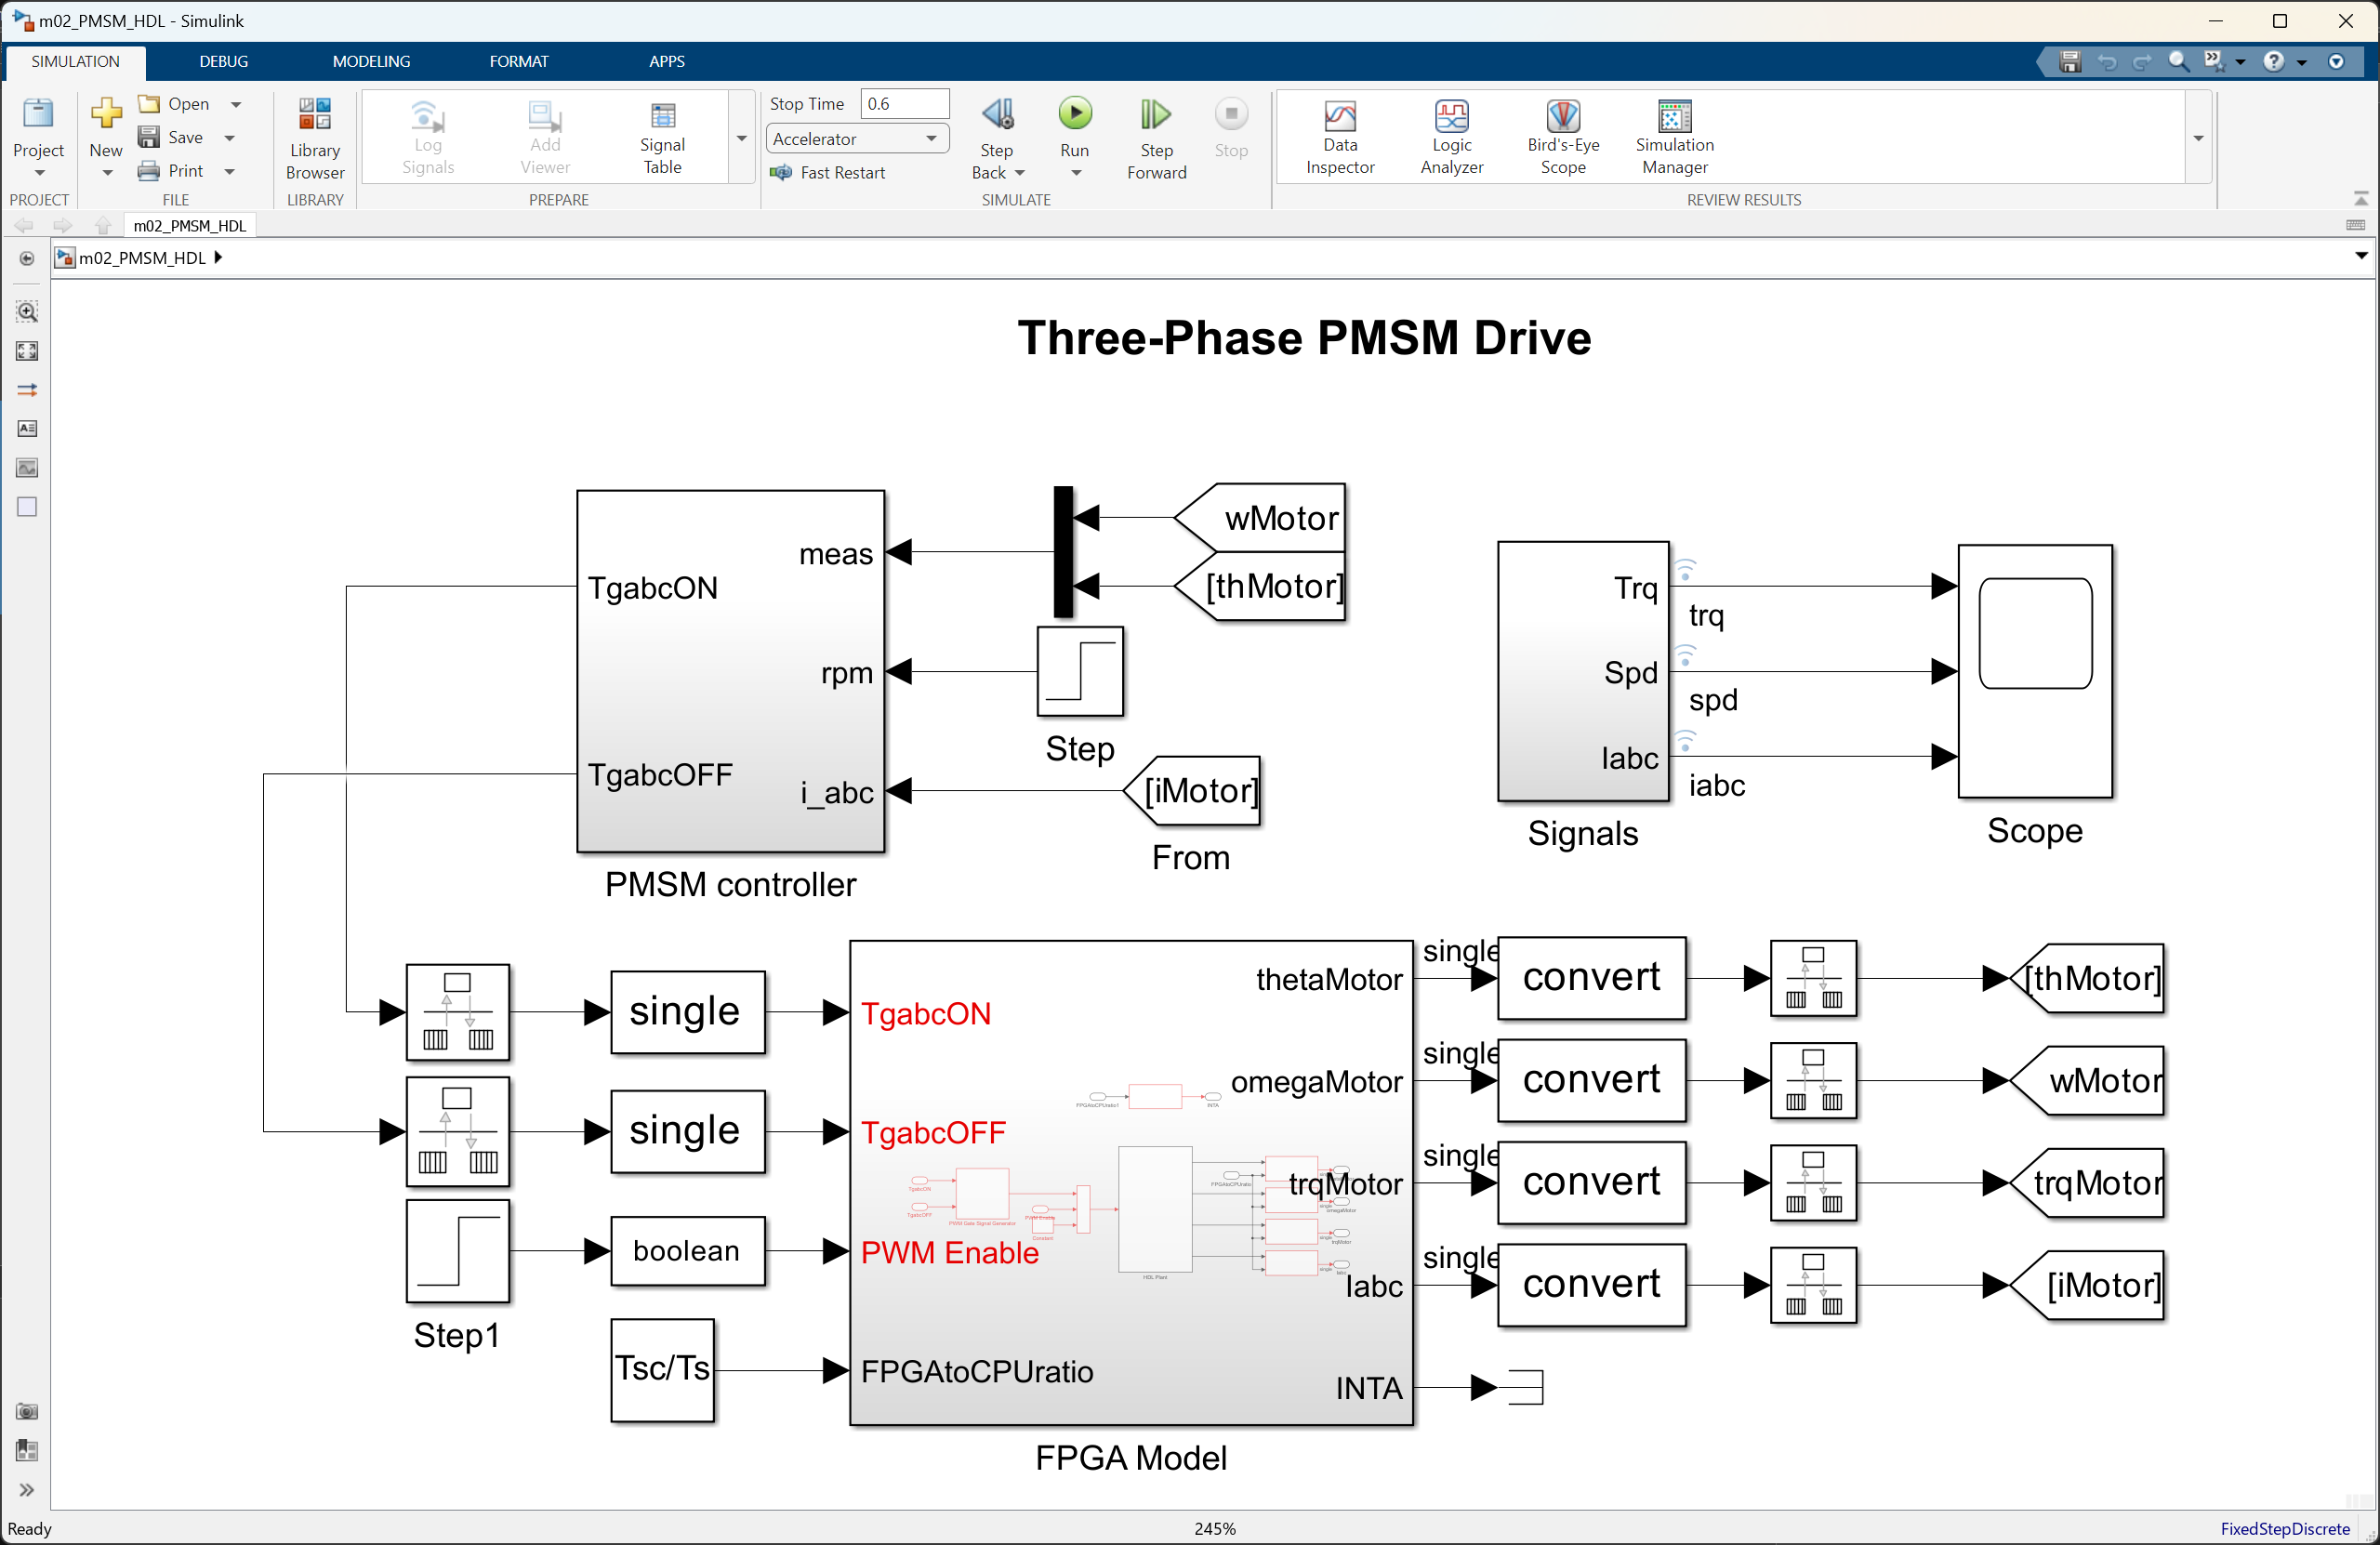

mdlHdl = 'm02_PMSM_HDL';
open_system(mdlHdl);

As of R2023a, this reconstruction requires some manual operations to reconnect the subsystems with the Pejovic approximated switches. However, this operation should be carried out only once and the proper port labelling makes the task a bit easier.

open_system([mdlHdl,'/FPGA Model']);
set_param([mdlHdl,'/FPGA Model/HDL Plant'],'LabelModeActiveChoice','Pejovic');

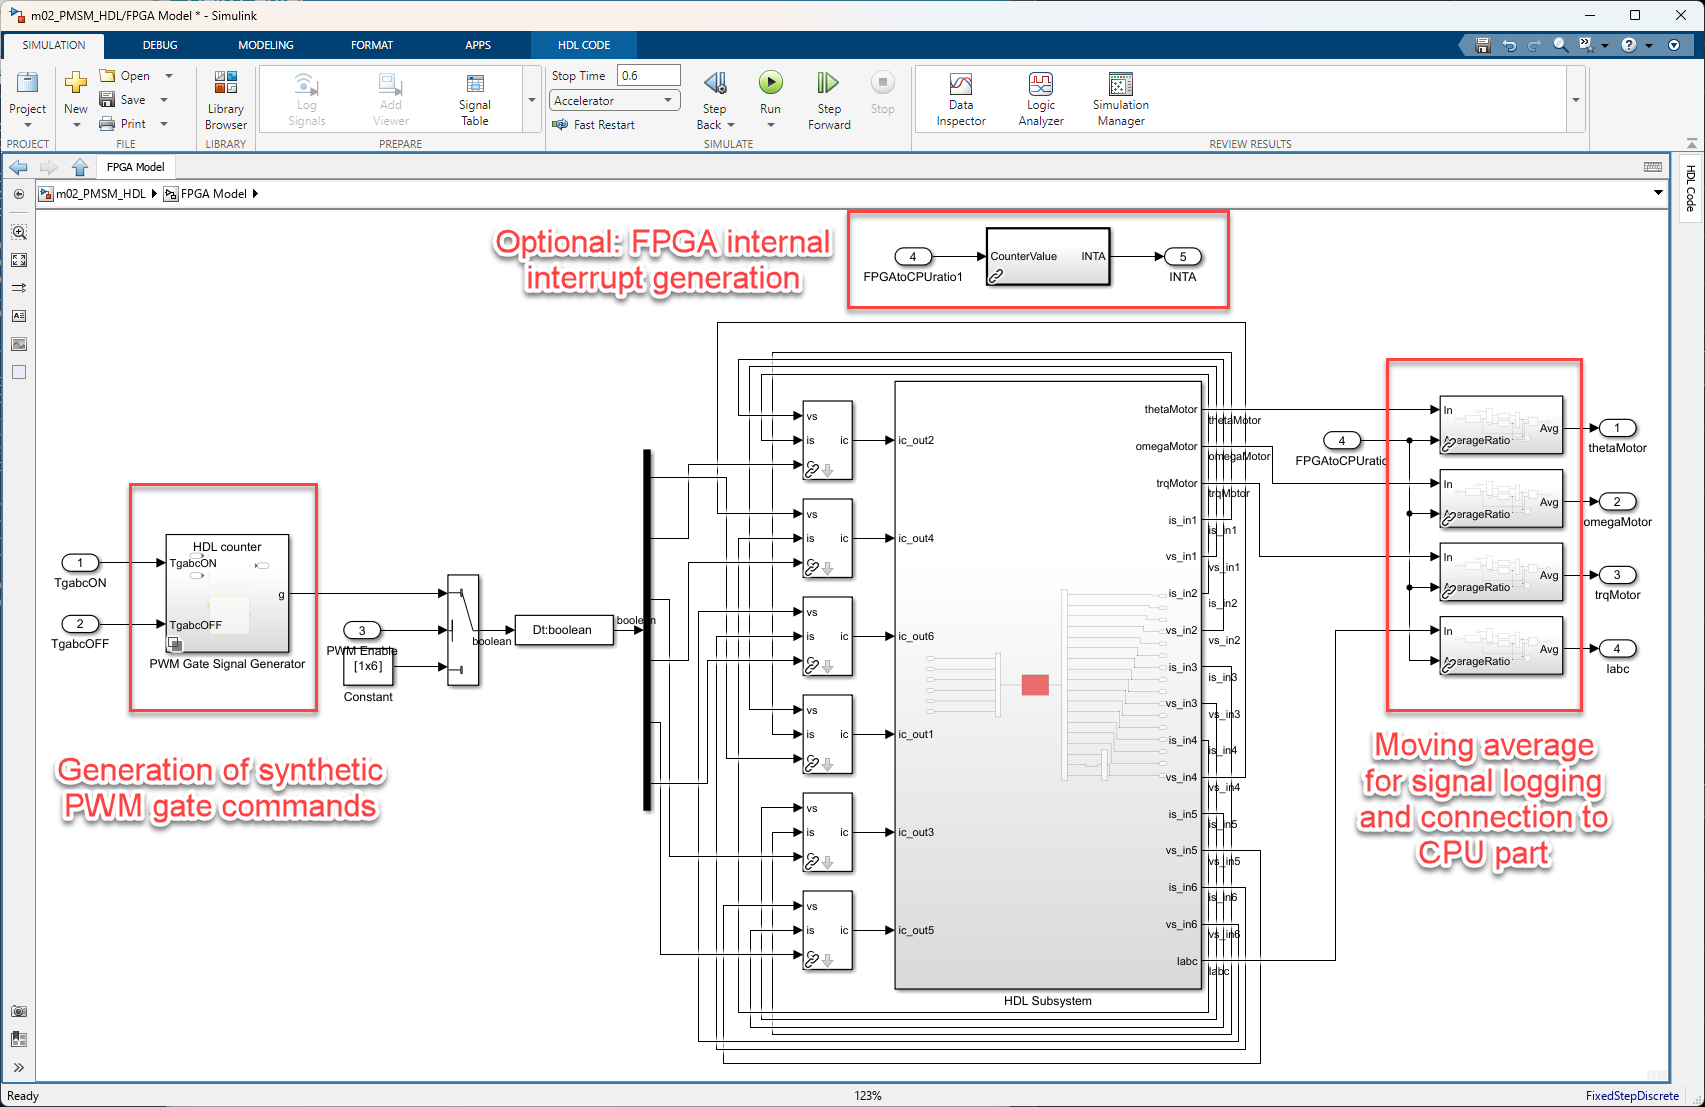

Please notice that we have enhanced the HDL-ready model with some subsystems highlighted below that are neccesary or very useful when generating an FPGA implementation:

- PWM Gate Signal Generator: this is an internal subsystem only used for debugging purposes, and to enable closed-loop simulation with the FPGA model even without having real digital inputs connected to the FPGA, or in other words, controller-independent FPGA model testing. In a real scenario, this subsystem is not present since the gate commands are digital inputs directly fed via the TTL lines represented by single boolean inports in the model.

- FPGA Interrupt Generation: this subsystem generates a pulse one every n FPGA model ticks, being n the ratio between the FPGA and the CPU models frequency. For example, if the FPGA model runs at 1MHz and the CPU part runs at 1kHz, the ratio will be 1000. This interrupt enables an accurate synchronization between the execution of the FPGA and CPU model.

- Moving Signal Average: since the FPGA model runs much faster than the CPU, it will generate results at a much faster rate. Other than very detailed debugging, we don't need such a detail of the model parts running on the FPGA. We can therefore average those values that the FPGA computes between every CPU sample, and pass only the averaged value to the CPU either for logging or to feed some other plant model or logic running on the CPU side.

One of the main benefits of this approach is that it is fully transparent, enabling us to observe and simulate the full model even before generating HDL code reusing the rest of the model that does not run on the CPU and we had available as part of the design or validation process.

set_param(mdlHdl,'SimulationMode','accelerator');
simOutHdl = sim(mdlHdl);

Please notice that we have set the simulation mode to accelerator to speed up the simulation on desktop, because now the sample time is much smaller representing the FPGA model rate we will eventually have running on the real-time simulator.

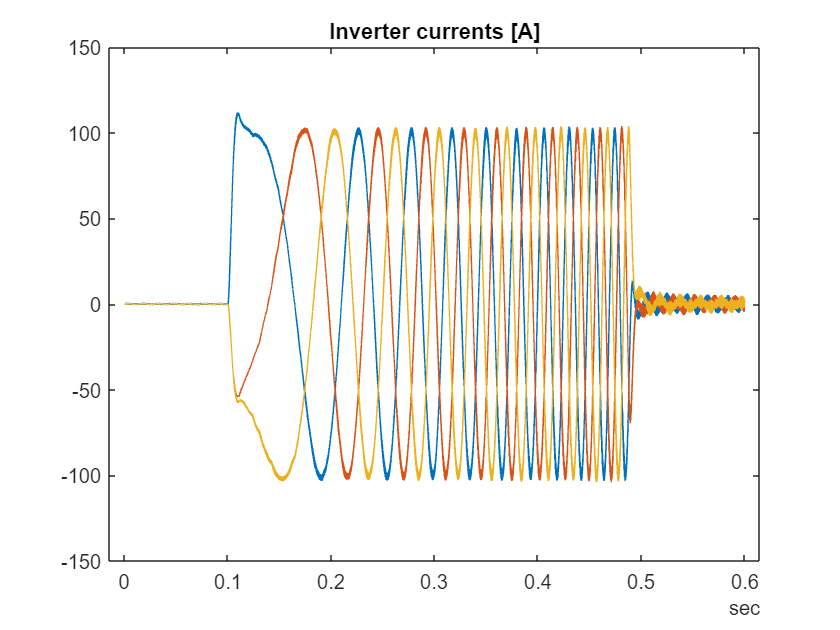

data = simOutHdl.logsout.getElement('iabc').extractTimetable;
plot(data.Time,data.Variables);
title('Inverter currents [A]');

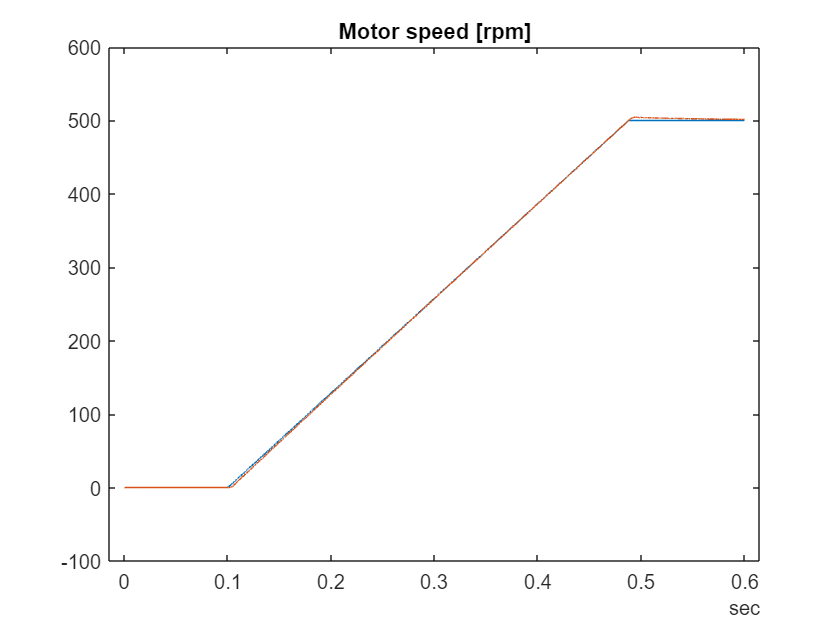

data = simOutHdl.logsout.getElement('spd').extractTimetable;
plot(data.Time,data.Variables);
title('Motor speed [rpm]');

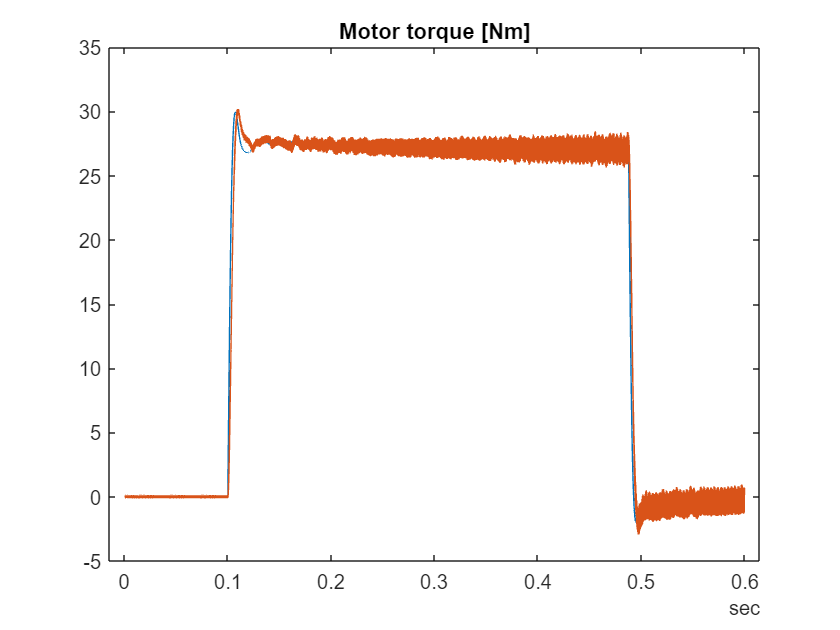

data = simOutHdl.logsout.getElement('trq').extractTimetable;
plot(data.Time,data.Variables);
title('Motor torque [Nm]');

Simulation results are apparently identical, or at least, very similar to those we had obtained with the source Simscape model. Let's take a closer look.

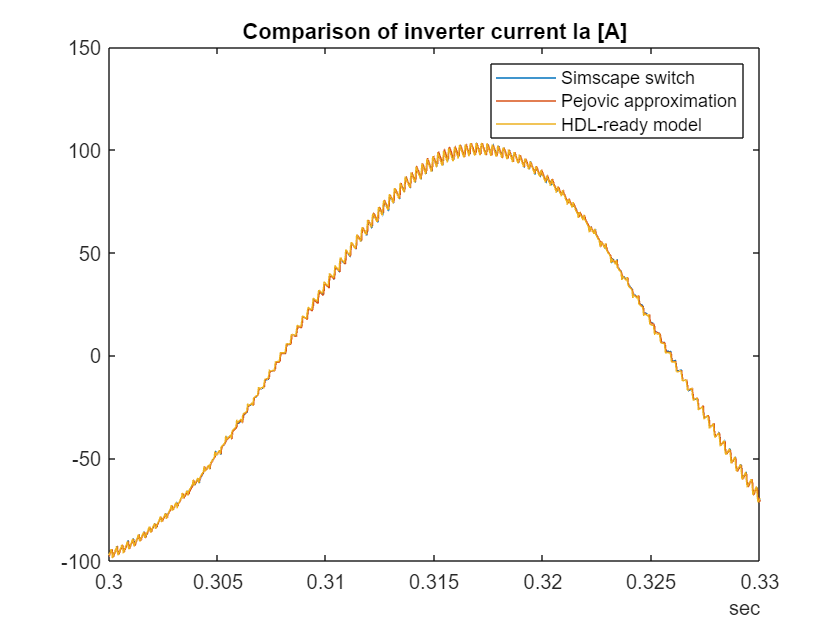

iabcPej = simOutPej.logsout.getElement('iabc').extractTimetable;
iabcSw = simOutSw.logsout.getElement('iabc').extractTimetable;
iabcHdl = simOutHdl.logsout.getElement('Iabc').extractTimetable;

plot(iabcSw.Time, iabcSw.iabc(:,1),...
    iabcPej.Time, iabcPej.iabc(:,1),...
    iabcHdl.Time, iabcHdl.Iabc(:,1));
title('Comparison of inverter current Ia [A]');
legend('Simscape switch','Pejovic approximation','HDL-ready model');
xlim([duration(0,0,0.300) duration(0,0,0.33)]);

Once we have validated the source model for the HDL code generation, we can generate HDL code and the current settings with the command below.

set_param([mdlHdl,'/FPGA Model/HDL Plant'],'LabelModeActiveChoice','Pejovic');
makehdl([mdlHdl,'/FPGA Model']);

### Begin compilation of the model 'm02_PMSM_HDL'...


### Generating HDL for 'm02_PMSM_HDL/FPGA Model'.
### Using the config set for model m02_PMSM_HDL for HDL code generation parameters.
### Running HDL checks on the model 'm02_PMSM_HDL'.
### Begin compilation of the model 'm02_PMSM_HDL'...


### Creating HDL Code Generation Check Report FPGA_Model_report.html
### HDL check for 'm02_PMSM_HDL' complete with 4 errors, 6 warnings, and 0 messages.


Error using slhdlcoder.HDLCoder/reporterrors

For the block 'm02_PMSM_HDL/FPGA Model/HDL Moving Average Tunable3/Divide'
   HDL code generation for block 'Divide' with fixed-point data supports only the 'ShiftAdd' architecture. To generate code with floating-point types, use 'Linear' architecture.

Error in slhdlcoder.HDLCoder/runCheckHdlAndPirFrontEnd

Error in slhdlcoder.HDLCoder/compileModelAndCreatePIR

Error in slhdlcoder.HDLCoder/makehdl

Error in privmakehdl

Error in makehdl (line 66)
privmakehdl(varargin{:})

In most of the cases though, the most appropiate step is to [open the HDL Workflow Advisor](matlab:hdladvisor([mdlHdl,'/FPGA Model']);) and set other important settings such as the I/O mapping, and even generate the FPGA bistream calling the synthesis tool in the background.

This model has already been configured with the required settings for the Speedgoat's IO334. Please feel free to explore the different steps for more details about the configuration required for a complete FPGA implementation. You can also explore the [HDL workflow script](matlab:open('hdlworkflow_allPCI')) if you want to fully automate the process. This script can be generated at any time from the HDL Workflow Advisor in the File menu.

### Comparison of HDL code efficiency and performance

In addition to the Pejovic optimized configuration for FPGA execution, we will generate HDL code from the standard configuration as created automatically by the Simscape to HDL Workflow Advisor and compare the HDL code generation report results.

To this end, first we switch the active variant for the HDL plant model, and generate HDL code leveraging the same HDL main model, settings and FPGA I/O configuration from the previous step.

set_param([mdlHdl,'/FPGA Model/HDL Plant'],'LabelModeActiveChoice','Standard');
makehdl([mdlHdl,'/FPGA Model']);

Among the different metrics included in the report, we will compare two that give us some information regarding the required FPGA resources and the maximum expected FPGA performance.

Please notice that whereas the estimated FPGA resources as a measure of total 1-bit registers is very similar, the critical path delay, which is a metric that determines how fast we can run our model on the FPGA is almost 50% better for the Pejovic approximation method. Therefore, any FPGA power electronics model that requires very fast PWM switching frequency must work leveraging the Pejovic approximation described here.

## Validation of HIL model and execution on FPGA-based Speedgoat target

Assuming that you have the tools and dependencies required (FPGA reference design and FPGA synthesis tool), you can complete the execution of the HDL Workflow Advisor, and it will generate a model where the FPGA subsystem has been replaced with a masked subsystem representing the FPGA implementation.

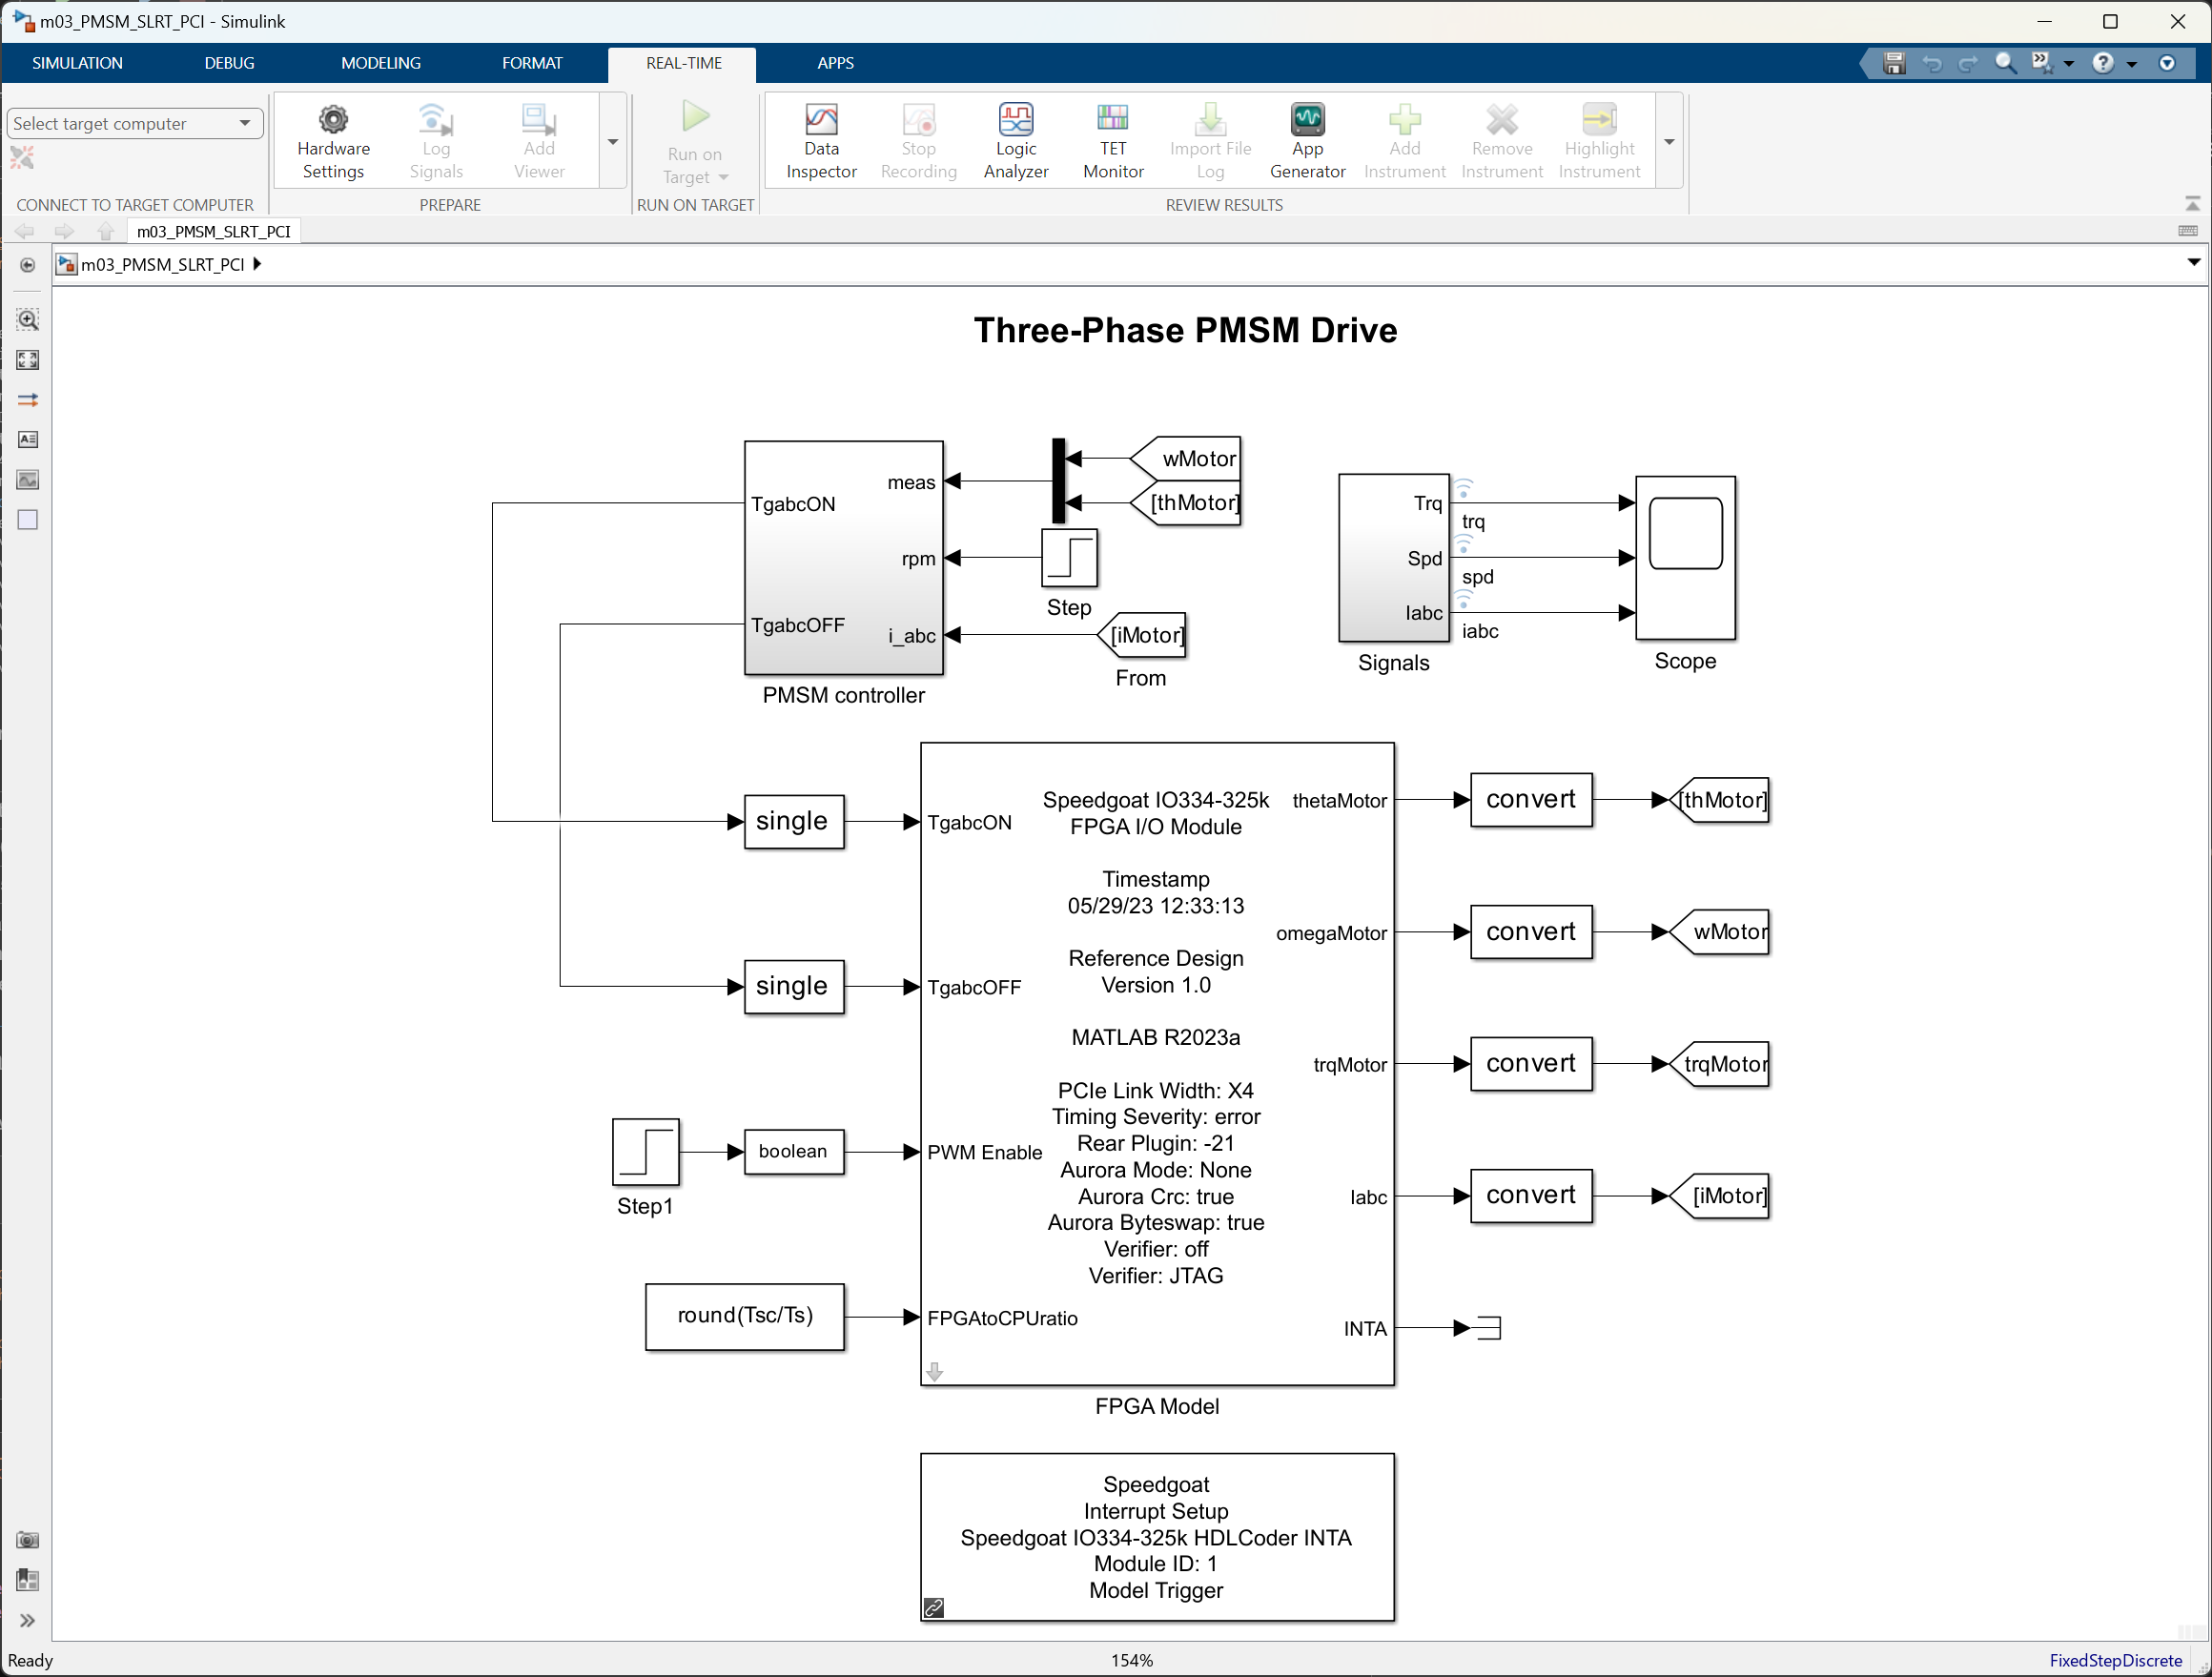

mdlHil = 'm03_PMSM_SLRT_PCI';
open_system(mdlHil);

This FPGA masked subsystem cannot be simulated on desktop, but it contains the required logic to be automatically deployed to the FPGA if we connect and load the resulting real-time application into a real-time target with the I/O modules compatible.

This model can be, for instance, executed in External Mode using the real-time tab on a Speedgoat target with an IO334 FPGA. Results will match those obtained in the previous chapter.